# Analytic Solutions to Foundational Ordinary and Partial Differential Equation Models of Biological Systems

By: Ethan Dintzner

## Description

This is a codebook that goes with the graphs in my paper "Analytical Solutions to Foundational Ordinary and Partial Differential Equation Models of Biological Systems".

### Imports

prettyfig_path =  '/Users/ethan/Yale University Dropbox/users/ethan_dintzner/code';% "D:\Yale University Dropbox\users\ethan_dintzner\code"; %
addpath(prettyfig_path);

% latex style graphs
set(groot, 'defaultAxesTickLabelInterpreter', 'latex'); 
set(groot, 'defaultLegendInterpreter', 'latex');        
set(groot, 'defaultColorbarTickLabelInterpreter', 'latex'); 
set(groot, 'defaultTextInterpreter', 'latex');          
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');

## Problem 2.1

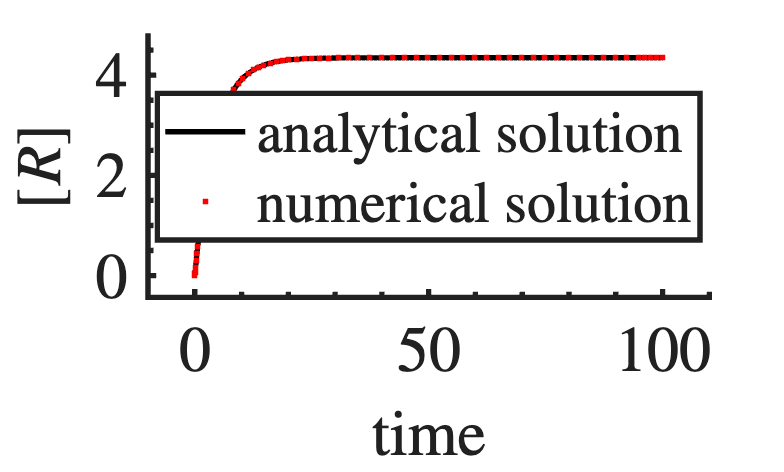

beta_R = 1; % molecules/s
alpha_R = 0.23; % /s
R0 = 0; % molecules

% analytical solution
function out = Rt(t,beta_R,alpha_R,R0)
    out = beta_R/alpha_R+(R0-beta_R/alpha_R)*exp(-alpha_R*t);
end

% ODE
function out = drdt(R,t,beta_R,alpha_R)
    out = beta_R - alpha_R*R;
end


tmin = 0;
tmax = 100;
t = tmin:0.001:tmax;

figure; hold on;
analytical_sol = Rt(t,beta_R,alpha_R,R0);
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, R) drdt(R, t, beta_R, alpha_R),[tmin,tmax],R0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[R]$')
PrettyFig;


$$X(t)=\frac{\beta_X\beta_R}{\alpha_X\alpha_R}+\frac{\beta_X\left(R_0-\frac{\beta_R}{\alpha_R}\right)}{\alpha_X-\alpha_R}e^{-\alpha_Rt}+Ce^{-\alpha_X t}\\
C=X_0-\frac{\beta_X\beta_R}{\alpha_X\alpha_R}-\frac{\beta_X\left(R_0-\frac{\beta_R}{\alpha_R}\right)}{\alpha_X-\alpha_R}$$


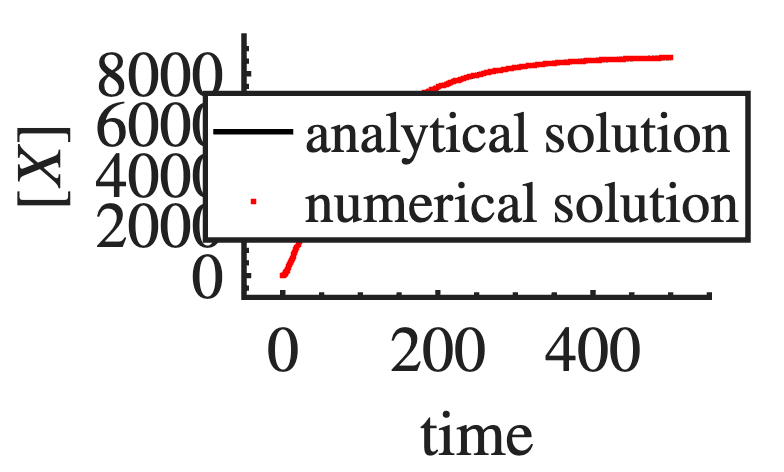

beta_X = 20; % each RNA produces ~20 protein
alpha_X = 0.01; % /s
X0 = 0;

% ODE
function drpdt = rp(t,y,beta_R,alpha_R,beta_X,alpha_X)
    drpdt = [beta_R-alpha_R*y(1); beta_X*y(1)-alpha_X*y(2)];
end

% analytical solution
function out = Xt(t,beta_X,alpha_X,beta_R,alpha_R,X0,R0)
    C = X0 - (beta_X*beta_R)/(alpha_X*alpha_R) - ((beta_X*(R0-(beta_R/alpha_R)))/(alpha_X-alpha_R));
    term1 = (beta_X*beta_R)/(alpha_X*alpha_R);
    term2 = ((beta_X*(R0-(beta_R/alpha_R)))/(alpha_X-alpha_R)).*exp(-alpha_R.*t);
    term3 = exp(-alpha_X.*t);
    out = term1+term2+C*term3;
end

tmin = 0;
tmax = 500;
t = tmin:0.001:tmax;

figure; hold on;
analytical_sol = Xt(t,beta_X,alpha_X,beta_R,alpha_R,X0,R0);
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, y) rp(t,y,beta_R,alpha_R,beta_X,alpha_X),[tmin,tmax],[R0,X0]);
plot(t_numer, numer_sol(:,2),'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[X]$')
PrettyFig;

## Problem 2.2


$$X(t)=\left(X_0+\frac{\beta}{\alpha^2+1}\right)e^{-\alpha t}-\frac{\beta}{\alpha^2+1}\cos t +\frac{\alpha\beta}{\alpha^2+1}\sin t$$


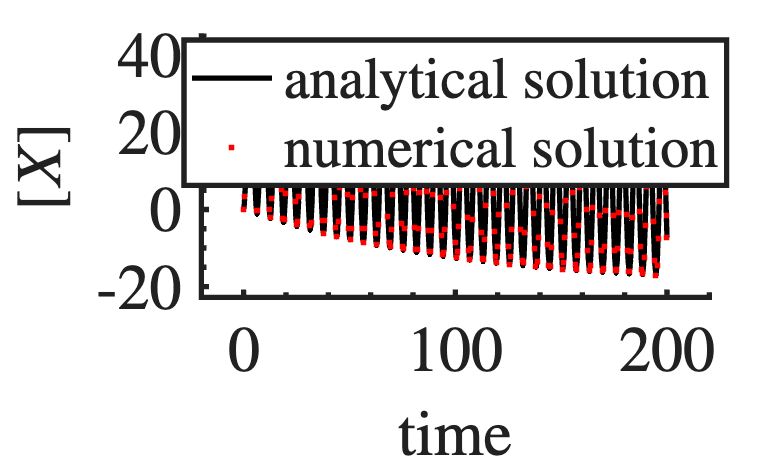

beta = 20; 
alpha = 0.01; 
X0 = 0;

% ODE
function out = dXdt(t,X,beta,alpha)
    out = beta*sin(t)-alpha*X;
end

% analytical solution
function out = Xt22(t,beta,alpha,X0)
    C = X0+beta/(alpha^2+1);
    term1 = exp(-alpha*t);
    term2 = -beta/(alpha^2+1)*cos(t);
    term3 = ((alpha*beta)/(alpha^2+1))*sin(t);
    out = C*term1+term2+term3;
end

tmin = 0;
tmax = 200;
t = tmin:0.001:tmax;

figure; hold on;
analytical_sol = Xt22(t,beta,alpha,X0);
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, X) dXdt(t,X,beta,alpha),[tmin,tmax],X0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[X]$')
PrettyFig;


$$X(t)=\left(X_0+\frac{\beta}{\alpha^2+1}-\frac{\beta}{\alpha}\right)e^{-\alpha t }-\frac{\beta}{\alpha^2+1}\cos t+\frac{\alpha\beta}{\alpha^2+1}\sin t+\frac{\beta}{\alpha}$$


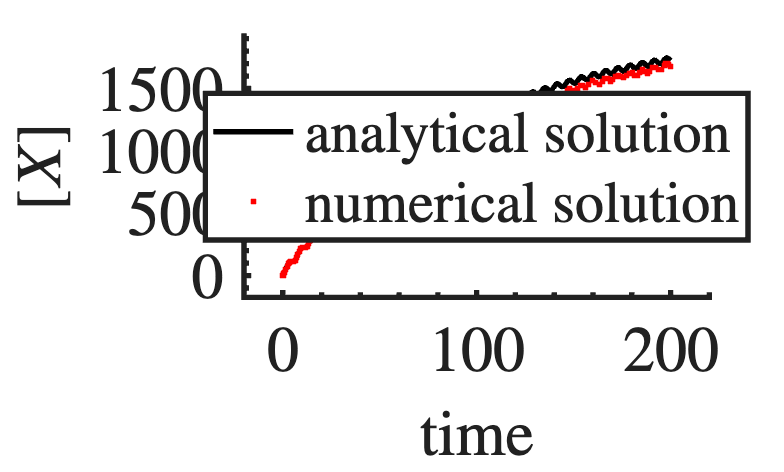

beta = 20; 
alpha = 0.01; 
X0 = 0;

% ODE
function out = dX22bdt(t,X,beta,alpha)
    out = beta*sin(t)+beta-alpha*X;
end

% analytical solution
function out = Xt22b(t,beta,alpha,X0)
    C = X0+beta/(alpha^2+1)-beta/alpha;
    term1 = exp(-alpha*t);
    term2 = -beta/(alpha^2+1)*cos(t);
    term3 = ((alpha*beta)/(alpha^2+1))*sin(t);
    term4 = beta/alpha;
    out = C*term1+term2+term3+term4;
end

tmin = 0;
tmax = 200;
t = tmin:0.001:tmax;

figure; hold on;
analytical_sol = Xt22b(t,beta,alpha,X0);
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, X) dX22bdt(t,X,beta,alpha),[tmin,tmax],X0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[X]$')
PrettyFig;

## Problem 2.3


$$Y(t)=Ce^{-\alpha_Yt}+\beta_YKe^{-\alpha_Yt}\int_0^t \frac{ e^{\alpha_Ys}}{K+\frac{\beta_X}{\alpha_X}+\left(X_0-\frac{\beta_X}{\alpha_X}\right)e^{-\alpha_Xs}}\,ds$$


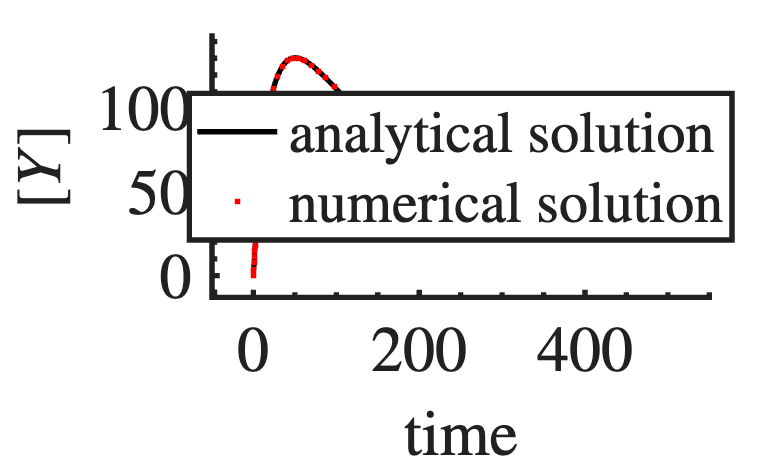

beta_Y = 10;
alpha_Y = 0.02;
beta_X = 20; 
alpha_X = 0.007; 
X0 = 0;
K = 300;
Y0 = 0;

% ODE
function out = dYdt(t,Y,beta_Y,alpha_Y,K,alpha_X,beta_X,X0)
    X = beta_X/alpha_X+(X0-beta_X/alpha_X)*exp(-alpha_X*t);
    out = beta_Y*(K/(K+X))-alpha_Y*Y;
end

% integral term from nonelementary analytic solution
function out = Yt_nonelem_comp(s, alpha_Y,K,alpha_X,beta_X,X0)
    out = exp(alpha_Y.*s) / (K+beta_X/alpha_X+(X0-beta_X/alpha_X).*exp(-alpha_X.*s));
end

tmin = 0;
tmax = 500;
t = tmin:0.001:tmax;

figure; hold on;
analytical_sol = zeros(length(t),1);
for i=1:length(t)
    analytical_sol(i) = Y0*exp(-alpha_Y*t(i))+beta_Y*K*exp(-alpha_Y*t(i))*integral(@(s) Yt_nonelem_comp(s, alpha_Y,K,alpha_X,beta_X,X0),0,t(i),'ArrayValued',true);
end
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, Y) dYdt(t,Y,beta_Y,alpha_Y,K,alpha_X,beta_X,X0),[tmin,tmax],Y0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[Y]$')
PrettyFig;


$$Y(t)=\beta_YK\frac{\left(\beta_X-X_0\alpha\right)\ln\left((\beta_X+K\alpha)e^{\alpha t} -\beta_X+X_0\alpha\right)\cdot e^{-\alpha t}+\left(\beta_X+K\alpha\right)}{\left(\beta_X+K\alpha\right)^2}+\left(X_0-\beta_YK\frac{\left(\beta_X-X_0\alpha\right)\ln\left((\beta_X+K\alpha) -\beta_X+X_0\alpha\right)+\left(\beta_X+K\alpha\right)}{\left(\beta_X+K\alpha\right)^2}\right)e^{-\alpha t}$$


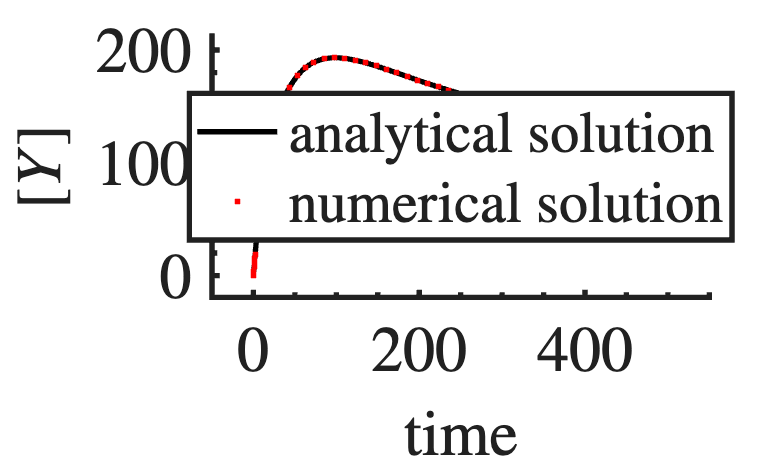

% closed form solution if \alpha_X=\alpha_Y
alpha = 0.01;
beta_Y = 10;
alpha_Y = alpha;
beta_X = 20; 
alpha_X = alpha;
X0 = 0;
K = 300;
Y0 = 0;
function out = Yt_elem(t,alpha,beta_X,beta_Y,K,X0,Y0)
    term1_numer = (beta_X-X0*alpha).*log((beta_X+K*alpha).*exp(alpha*t)-beta_X+X0*alpha).*exp(-alpha*t)+(beta_X+K*alpha);
    term1_denom = (beta_X+K*alpha)^2;  
    C_numer = (beta_X-X0*alpha)*log(K*alpha + X0*alpha) + (beta_X+K*alpha);
    C_denom = (beta_X+K*alpha)^2;
    out = beta_Y*K*(term1_numer/term1_denom) + (Y0-beta_Y*K*(C_numer/C_denom))*exp(-alpha*t);
end

figure; hold on;
analytical_sol = Yt_elem(t,alpha,beta_X,beta_Y,K,X0,Y0);
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, Y) dYdt(t,Y,beta_Y,alpha_Y,K,alpha_X,beta_X,X0),[tmin,tmax],Y0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[Y]$')
PrettyFig;


$$Y(t)=\frac{\beta_X\beta_Y}{\alpha}\frac{\left(\beta_X-X_0\alpha\right)\ln\left((\beta_X+K\alpha)e^{\alpha t} -\beta_X+X_0\alpha\right)e^{-\alpha t}+\left(\beta_X+K\alpha\right)}{\left(\beta_X+K\alpha\right)^2}\\\quad\quad+\beta_Y\left(X_0-\frac{\beta_X}{\alpha}\right)\frac{\ln\left(\left(\beta_X+K\alpha\right)e^{\alpha t}-\beta_X+X_0\alpha\right)}{\beta_X+K\alpha }e^{-\alpha t}+Ce^{-\alpha t}$$


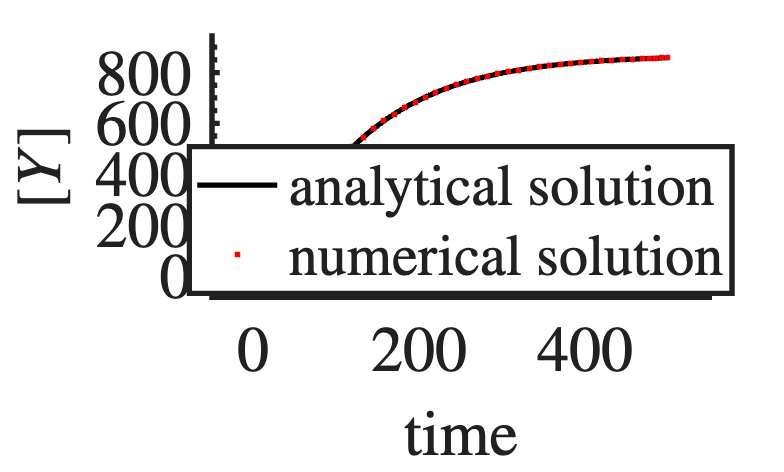

alpha = 0.01;
beta_Y = 10;
alpha_Y = alpha;
beta_X = 20; 
alpha_X = alpha;
X0 = 0;
K = 300;
Y0 = 0;

% ODE
function out = dY2dt(t,Y,beta_Y,alpha_Y,K,alpha_X,beta_X,X0)
    X = beta_X/alpha_X+(X0-beta_X/alpha_X)*exp(-alpha_X*t);
    out = beta_Y*(X/(K+X))-alpha_Y*Y;
end

% analytic solution for inhibitor, assuming alpha_X=alpha_Y
function out = Yt2_elem(t,alpha,beta_X,beta_Y,K,X0,Y0)
    term1_numer = (beta_X-X0*alpha).*log((beta_X+K*alpha).*exp(alpha.*t)-beta_X+X0*alpha).*exp(-alpha.*t)+(beta_X+K*alpha);
    term1_denom = (beta_X+K*alpha)^2;  
    term2_numer = log((beta_X+K*alpha).*exp(alpha.*t)-beta_X+X0*alpha);
    term2_denom = beta_X+K*alpha;
    C_term1_numer = (beta_X-X0*alpha)*log(K*alpha+X0*alpha)+(beta_X+K*alpha);
    C_term1_denom = term1_denom;
    C_term2_numer = log(K*alpha+X0*alpha);
    C_term2_denom = term2_denom;
    
    out = ((beta_X*beta_Y)/alpha).*(term1_numer./term1_denom) + ...
          beta_Y.*(X0-(beta_X/alpha)).*(term2_numer./term2_denom).*exp(-alpha.*t) + ...
          (Y0 - ((beta_X*beta_Y)/alpha).*(C_term1_numer./C_term1_denom) - ...
           beta_Y.*(X0-(beta_X/alpha)).*(C_term2_numer./C_term2_denom)) .* exp(-alpha.*t);
end

figure; hold on;
analytical_sol = Yt2_elem(t,alpha,beta_X,beta_Y,K,X0,Y0);
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, Y) dY2dt(t,Y,beta_Y,alpha_Y,K,alpha_X,beta_X,X0),[tmin,tmax],Y0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[Y]$')
PrettyFig;

Exploring the inhibition function of a gene negatively regulated by highly cooperative binding.

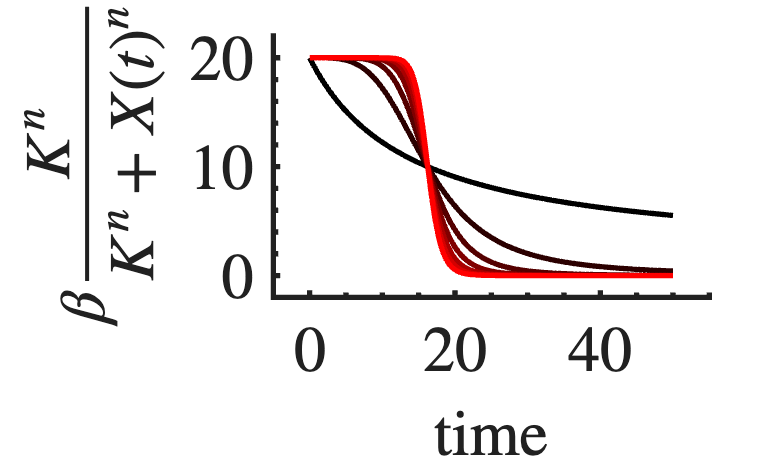

function out = hill_inhibition(t,K,n,beta,alpha,X0)
    Xt = beta/alpha + (X0-beta/alpha)*exp(-alpha*t);
    out = beta*K^n./(K^n+Xt.^n);
end

X0=0;
figure; hold on;
tmin = 0;
tmax = 50;
t = tmin:0.001:tmax;
ns = 1:3:21;

cmap = [linspace(0, 1, length(ns))', zeros(length(ns), 1), zeros(length(ns), 1)];
for i = 1:length(ns)
    plot(t, hill_inhibition(t,K,ns(i),beta_X,alpha_X,X0), 'Color', cmap(i,:))
    % tau = -(1/alpha_X) * log((K-beta_X/alpha_X)/(X0-beta_X/alpha_X));
    % xline(tau,'b');
end

xlabel('time')
ylabel('$\beta\frac{K^n}{K^n+X(t)^n}$')
PrettyFig;


$$Y(t)=\frac{\beta}{\alpha}+\left(Y_0-\frac{\beta}{\alpha}\right)e^{-\alpha t}+\frac{\beta}{\alpha}\left(e^{-\alpha (t-\tau)}-1\right)u_\tau(t)$$



$$X(t)=\frac{\beta}{\alpha}+\left(X_0-\frac{\beta}{\alpha}\right)e^{-\alpha t}$$


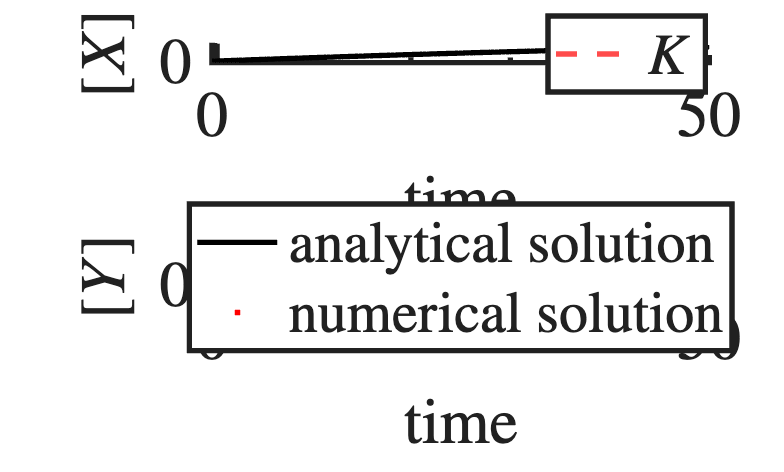

function out = dYdt_hill(t,Y,alpha,beta,tau)
    out = (1-(t>tau))*beta-alpha*Y;
end

function out = Yt_hill(t,alpha,beta,Y0,tau)
    out = beta/alpha + (Y0-beta/alpha)*exp(-alpha.*t)+((beta/alpha)*exp(-alpha.*(t-tau))-beta/alpha).*(t>tau);
end

X0 =0;
Y0 = 0;
K = 1500;
tau = (-(1/alpha_X)*log((K-(beta_X/alpha_X))/(X0-(beta_X/alpha_X))))*(X0<K);

figure; hold on;
subplot(2,1,1)
plot(t, beta_X/alpha_X+(X0-beta_X/alpha_X).*exp(-alpha_X*t),'k','HandleVisibility','off')
yline(K,'--r','DisplayName','$K$')
xlabel('time')
ylabel('$[X]$')
legend('Location','best')
box off;
subplot(2,1,2); hold on;
analytical_sol = Yt_hill(t,alpha_X,beta_X,Y0,tau);
plot(t, analytical_sol,'Color','k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, Y) dYdt_hill(t,Y,alpha_X,beta_X,tau),[tmin,tmax],Y0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
legend('Location','best')
xlabel('time')
ylabel('$[Y]$')
linkaxes(findobj(gcf,'Type','axes'),'x');
PrettyFig;

## Problem 2.4


$$X(t)=X_0e^{-\alpha t}+\sum_{i=1}^n\frac{\beta_i}{\alpha}\left[\left(1-e^{-\alpha(t-a_i)}\right)u_{a_i}(t)+\left(e^{-\alpha(t-b_i)}-1\right)u_{b_i}(t)\right]$$


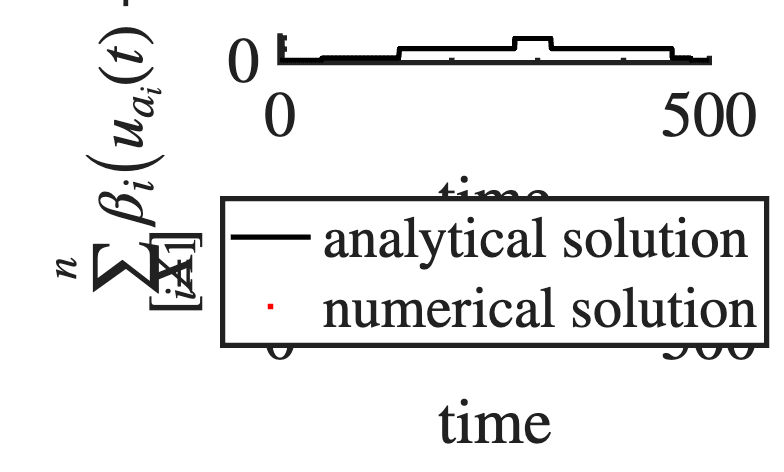

% time
tmin = 0;
tmax = 500;
t = tmin:0.001:tmax;

% step signal generation
n = 3;
beta = unifrnd(1,10,n,1);
pairs = sort(unifrnd(0,max(t),n,2),2);
a = pairs(:,1);
b = pairs(:,2);
signal = zeros(1,length(t));
for i=1:n 
    signal = signal + beta(i)*((a(i)<t)-(b(i)<t));
end

function out = dXdt_ode(t,X,alpha,beta,a,b)
    signal = zeros(1,length(t));
    for i=1:length(beta) 
        signal = signal + beta(i)*((a(i)<t)-(b(i)<t));
    end
    out = signal' - alpha*X;
end

function out = Xt_steps(t,X0,alpha,beta,a,b)
    term1 = X0*exp(-alpha*t);
    term2 = zeros(1,length(t));
    for i=1:length(beta) 
        term2 = term2 + (beta(i)/alpha).* ((1-exp(-alpha.*(t-a(i)))).*(a(i)<t) ...
                                         +(exp(-alpha.*(t-b(i)))-1).*(b(i)<t));
    end 
    out = term1 + term2;
end
figure; 
subplot(2,1,1); hold on;
plot(t,signal,'k')
xlabel('time')
ylabel('$\sum\limits_{i=1}^n\beta_i\left(u_{a_i}(t)-u_{b_i}(t)\right)$')
subplot(2,1,2); hold on;
plot(t, Xt_steps(t,X0,alpha_X,beta,a,b),'k','DisplayName','analytical solution')
[t_numer, numer_sol] = ode45(@(t, X) dXdt_ode(t,X,alpha_X,beta,a,b),[tmin,tmax],X0);
plot(t_numer, numer_sol,'.r','DisplayName','numerical solution')
xlabel('time')
ylabel('$[X]$')
legend('Location','best')
linkaxes(findobj(gcf,'Type','axes'),'x');
PrettyFig;

## Problem 2.5

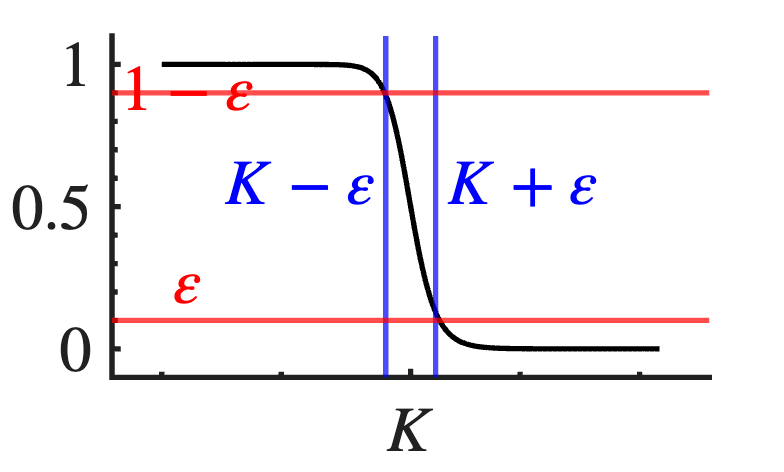

function out = hill_inhibition_rate(X,K,n)
    out = K^n./(K^n+X.^n);
end

K = 1;
n = 20;
X = 0:0.01:2;
epsilon = 0.1;

figure; hold on;
plot(X, hill_inhibition_rate(X,K,n), 'k')
xline(K-epsilon,'b')
text(K-epsilon-0.02, 0.45, '$K-\varepsilon$', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom', 'Color', 'b')
xline(K+epsilon,'b')
text(K+epsilon+0.02, 0.45, '$K+\varepsilon$', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom', 'Color', 'b')
text(0.1, epsilon , '$\varepsilon$', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', 'r')
yline(epsilon,'r')
yline(1-epsilon,'r')
text(0.1, 1-epsilon-0.12 , '$1-\varepsilon$', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', 'r')
xticks([1]); % Set x-ticks to only show at x=1
xticklabels({'$K$'}); % Label the x-tick at x=1 with $K$
set(gca, 'XMinorTick', 'on'); % Keep minor ticks on
set(gca, 'XTick', [1]); % Ensure only the tick at x=1 is shown
PrettyFig;

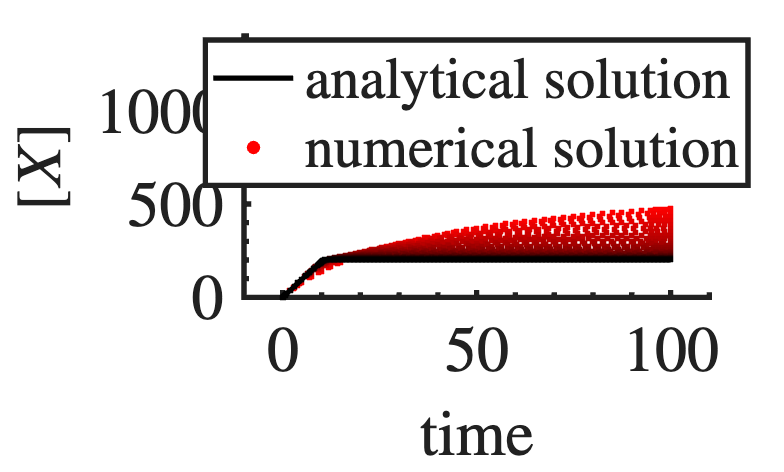

function out = hill_autoinhibition_ODE(X,t,K,n,beta,alpha)
    out = beta*K^n./(K^n+X.^n) - alpha*X;
end

function out = hill_autoinhibition_exact(t,K,beta,alpha,X0)
    tau = -(1/alpha)*log((K-beta/alpha)/(X0-beta/alpha));
    out = K*(tau<t) + (t<tau).*(beta/alpha + (X0-beta/alpha).*exp(-alpha.*t));
end

X0=0;
tmin = 0;
tmax = 100;
t = tmin:0.001:tmax;
beta = 20; % each RNA produces ~20 protein
% Ks = [200,500,1000];
K = 200;
alpha = 0.01; % /s
ns = logspace(0,2,30);% 1:1:60;
figure; hold on;
cmap = [linspace(0, 1, length(ns))', zeros(length(ns), 1), zeros(length(ns), 1)];
for i = 1:length(ns)
    [t_numer, numer_sol] = ode45(@(t, X) hill_autoinhibition_ODE(X,t,K,ns(i),beta,alpha),[tmin,tmax],X0);
    plot(t_numer, numer_sol, '.r','Color', cmap(int32(length(ns)+1-i),:),'HandleVisibility','off')
end
plot(t, hill_autoinhibition_exact(t,K,beta,alpha,X0),'k','HandleVisibility','off')
% title(['$K=',num2str(Ks(j)),'$'])
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5);  % Dummy line
h2 = plot(NaN, NaN, 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'r');  % Dummy dots
legend([h1, h2], {'analytical solution', 'numerical solution'}, 'Location', 'best');
ylim([0,(beta/alpha)*0.7])

% for j = 1:length(Ks)
%     cmap = [linspace(0, 1, length(ns))', zeros(length(ns), 1), zeros(length(ns), 1)];
%     subplot(3,1,j)
%     hold on;
%     for i = 1:length(ns)
%         [t_numer, numer_sol] = ode45(@(t, X) hill_autoinhibition_ODE(X,t,Ks(j),ns(i),beta,alpha),[tmin,tmax],X0);
%         plot(t_numer, numer_sol, '.r','Color', cmap(int32(length(ns)+1-i),:),'HandleVisibility','off')
%     end
%     plot(t, hill_autoinhibition_exact(t,Ks(j),beta,alpha,X0),'k','HandleVisibility','off')
%     % title(['$K=',num2str(Ks(j)),'$'])
%     h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5);  % Dummy line
%     h2 = plot(NaN, NaN, 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'r');  % Dummy dots
%     legend([h1, h2], {'analytical solution', 'numerical solution'}, 'Location', 'best');
%     xlabel('time')
%     ylabel('$[X]$')
% end
% linkaxes(findobj(gcf,'Type','axes'),'x');
xlabel('time')
ylabel('$[X]$')
PrettyFig;

## Positive Autoregulation Case

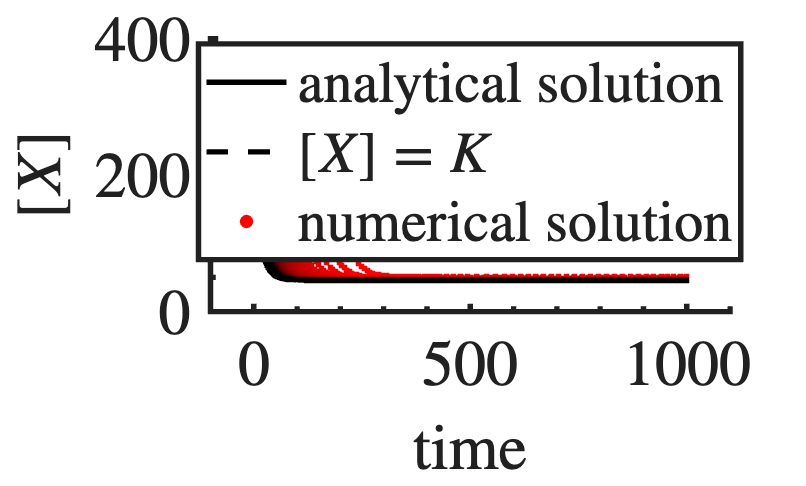

function out = hill_autoactivation_ODE(X,t,K,n,beta,alpha,gamma)
    out = gamma + (beta*X^n)./(K^n+X.^n) - alpha*X;
end

function out = hill_autoactivation_exact(t,K,beta,alpha,gamma,X0)
    if X0<K
        out = gamma/alpha + (X0-gamma/alpha).*exp(-alpha.*t);

    elseif X0==K
        out = K*ones(1,length(t));

    elseif K<X0
        out = (beta+gamma)/alpha + (X0-(beta+gamma)/alpha).*exp(-alpha.*t);
    end
end

tmin = 0;
tmax = 1000;
t = tmin:0.001:tmax;
beta = 20; % each RNA produces ~20 protein
gamma = 3; % valid leaky expression to satisfy positive autoregulation in limit of high n
K = 200;
alpha = 0.065; % /s
ns = logspace(0.48,1,30);% 1:1:60;
figure; hold on;
cmap = [linspace(0, 1, length(ns))', zeros(length(ns), 1), zeros(length(ns), 1)];

% lower initial condition 
X0= 195;
for i = 1:length(ns)
    [t_numer, numer_sol] = ode45(@(t, X) hill_autoactivation_ODE(X,t,K,ns(i),beta,alpha,gamma),[tmin,tmax],X0);
    plot(t_numer, numer_sol, '.r','Color', cmap(int32(length(ns)+1-i),:),'HandleVisibility','off')
end
plot(t, hill_autoactivation_exact(t,K,beta,alpha,gamma,X0),'k','HandleVisibility','off')

% upper initial condition
X0= 205;
for i = 1:length(ns)
    [t_numer, numer_sol] = ode45(@(t, X) hill_autoactivation_ODE(X,t,K,ns(i),beta,alpha,gamma),[tmin,tmax],X0);
    plot(t_numer, numer_sol, '.r','Color', cmap(int32(length(ns)+1-i),:),'HandleVisibility','off')
end
plot(t, hill_autoactivation_exact(t,K,beta,alpha,gamma,X0),'k','HandleVisibility','off')
plot([0,tmax],[K,K],'k--')

% title(['$K=',num2str(Ks(j)),'$'])
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5);  % Dummy line
h2 = plot(NaN, NaN, 'k--', 'LineWidth', 1.5);  % Dummy line
h3 = plot(NaN, NaN, 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'r');  % Dummy dots
legend([h1, h2, h3], {'analytical solution', '$[X]=K$','numerical solution'}, 'Location', 'best');
% ylim([0,(beta/alpha)*0.7])
yl = ylim(gca);
ylim([0, yl(2)]);
xlabel('time')
ylabel('$[X]$')
PrettyFig;

## Problem 2.7


$$X(t)=X_0e^{-\alpha_Xt}+\int_0^tf(t-\tau)e^{-\alpha_X\tau}\,d\tau$$



$$Y(t)=Y_0e^{-\alpha_Yt}+\beta_Y\int_0^tu(X(\tau)-K)e^{-\alpha_Y(t-\tau)}\,d\tau$$


AND logic:


$$Z(t)=Z_0e^{-\alpha_Zt}+\beta_Z\int_0^tu\big(X(\tau)-K_X)\cdot u\big(Y(\tau)-K_Y)e^{-\alpha_Z(t-\tau)}\,d\tau$$


AND NOT logic:


$$Z(t)=Z_0e^{-\alpha_Zt}+\beta_Z\int_0^tu\big(X(\tau)-K_X)\cdot \big(1-u(Y(\tau)-K_Y)\big)e^{-\alpha_Z(t-\tau)}\,d\tau$$


OR logic:


$$Z(t)=\beta_Z\int_0^t\left[1-\big(1-u(X(\tau)-K_X)\big)\cdot \big(1-u(Y(\tau)-K_Y)\big)\right]\cdot e^{-\alpha (t-\tau)}\,d\tau+Z_0e^{-\alpha_Zt}$$


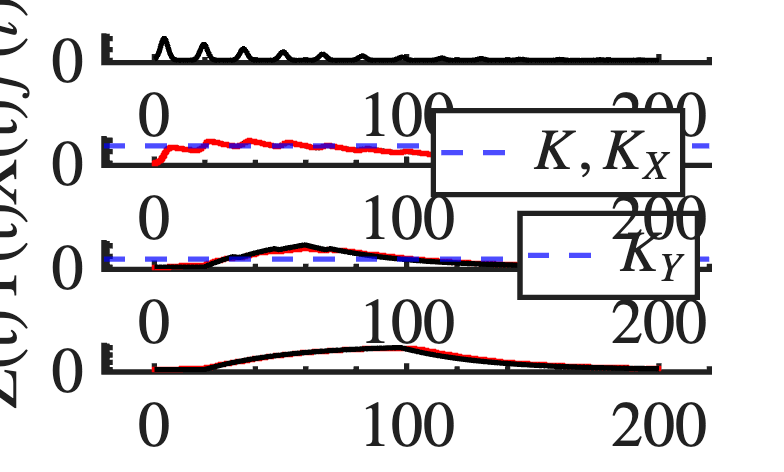

function out = f_input(t)
    % out = 5*((25<t)-(50<t)+(70<t)-(80<t));
    out = 1.1*exp(3*sin(0.4*t)).*exp(-t/50);
end

function out = Z_AND(t, L, f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y, n)
    X = L(1);
    Y = L(2);
    Z = L(3);
    dXdt = f_input(t) - alpha_X*X;
    dYdt = beta_Y.*(X.^n)./(X.^n+K^n) - alpha_Y*Y;
    dZdt = beta_Z.*((X.^n)./(X.^n+K_X^n)).*((Y.^n)./(Y.^n+K_Y^n)) - alpha_Z*Z;
    out  = [dXdt; dYdt; dZdt];
end

function out = Z_AND_exact(t,f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y,X0,Y0,Z0)
    X_t = conv(f_input(t), exp(-alpha_X*t))*0.001;
    X_t = X0*exp(-alpha_X*t) + X_t(1:length(t));
    Y_t = beta_Y*conv(X_t>K, exp(-alpha_X*t))*0.001;
    Y_t = Y0*exp(-alpha_Y*t)+Y_t(1:length(t));
    Z_t = beta_Z*conv((X_t>K_X).*(Y_t>K_Y),exp(-alpha_Z*t))*0.001;
    Z_t = Z0*exp(-alpha_Z*t)+Z_t(1:length(t));
    out = [X_t; Y_t; Z_t];
end

function out = Z_AND_NOT(t, L, f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y, n)
    X = L(1);
    Y = L(2);
    Z = L(3);
    dXdt = f_input(t) - alpha_X*X;
    dYdt = beta_Y.*(X.^n)./(X.^n+K^n) - alpha_Y*Y;
    dZdt = beta_Z.*((X.^n)./(X.^n+K_X^n)).*((K_Y.^n)./(Y.^n+K_Y^n)) - alpha_Z*Z;
    out  = [dXdt; dYdt; dZdt];
end

function out = Z_AND_NOT_exact(t,f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y,X0,Y0,Z0)
    X_t = conv(f_input(t), exp(-alpha_X*t))*0.001;
    X_t = X0*exp(-alpha_X*t) + X_t(1:length(t));
    Y_t = beta_Y*conv(X_t>K, exp(-alpha_X*t))*0.001;
    Y_t = Y0*exp(-alpha_Y*t)+Y_t(1:length(t));
    Z_t = beta_Z*conv((X_t>K_X).*(1-(Y_t>K_Y)),exp(-alpha_Z*t))*0.001;
    Z_t = Z0*exp(-alpha_Z*t)+Z_t(1:length(t));
    out = [X_t; Y_t; Z_t];
end

function out = Z_OR(t, L, f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y, n)
    X = L(1);
    Y = L(2);
    Z = L(3);
    dXdt = f_input(t) - alpha_X*X;
    dYdt = beta_Y.*(X.^n)./(X.^n+K^n) - alpha_Y*Y;
    dZdt = beta_Z.*(1-((K.^n)./(X.^n+K_X^n)).*((K_Y.^n)./(Y.^n+K_Y^n))) - alpha_Z*Z;
    out  = [dXdt; dYdt; dZdt];
end

function out = Z_OR_exact(t,f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y,X0,Y0,Z0)
    X_t = conv(f_input(t), exp(-alpha_X*t))*0.001;
    X_t = X0*exp(-alpha_X*t) + X_t(1:length(t));
    Y_t = beta_Y*conv(X_t>K, exp(-alpha_X*t))*0.001;
    Y_t = Y0*exp(-alpha_Y*t)+Y_t(1:length(t));
    Z_t = beta_Z*conv(1-(1-(X_t>K_X)).*(1-(Y_t>K_Y)),exp(-alpha_Z*t))*0.001;
    Z_t = Z0*exp(-alpha_Z*t)+Z_t(1:length(t));
    out = [X_t; Y_t; Z_t];
end

% parameters 
beta_Y = 10; beta_Z = beta_Y; % production
alpha_X = 0.03; alpha_Y = 0.03; alpha_Z = alpha_X; % degradation
K = 75; K_X = K; K_Y = K; % binding constants
X0 = 0; Y0 = 0; Z0 = 0; % initial conditions
n = 10; % cooperativity

% time
tmin = 0;
tmax = 200;
t = tmin:0.001:tmax;

% exact solution
out = Z_OR_exact(t,@f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y,X0,Y0,Z0);
X_t = out(1,:); Y_t = out(2,:); Z_t = out(3,:); 

% numerical solution
F = @(t,L) Z_OR(t, L, @f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y, n);
[t_out, L_out] = ode45(F, [tmin tmax], [X0; Y0; Z0]);

% plot the solution
figure; 
subplot(4,1,3); hold on;
scatter(t_out,L_out(:,2),'.r','HandleVisibility','off')
subplot(4,1,4); hold on;
scatter(t_out,L_out(:,3),'.r','HandleVisibility','off')

% exact solution
subplot(4,1,1); hold on;
plot(t,f_input(t),'k')
ylabel('$f(t)$')
subplot(4,1,2); hold on;
plot(t,X_t,'k','HandleVisibility','off')
scatter(t_out,L_out(:,1),'.r','HandleVisibility','off')
yline(K,'--b','DisplayName','$K,K_X$');
legend('Location','best');
ylabel('X(t)')
subplot(4,1,3); hold on;
plot(t,Y_t,'k','HandleVisibility','off')
yline(K_Y,'--b','DisplayName','$K_Y$');
legend('Location','best');
ylabel('Y(t)')
subplot(4,1,4);hold on;
plot(t,Z_t,'k','HandleVisibility','off')
ylabel('Z(t)')

PrettyFig;

Compute numerical solutions as a limit of $n$. 

yes_save = false

yes_save = logical
   1


ns = logspace(0,2,10);
cmap = [linspace(0, 1, length(ns))', zeros(length(ns), 1), zeros(length(ns), 1)];
figure; 

% numerical solution for different n
for i=1:length(ns)
    F = @(t,L) Z_OR(t, L, @f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y, ns(i));
    [t_out, L_out] = ode45(F, [tmin tmax], [X0; Y0; Z0]);
    
    % plot the solution
    subplot(4,1,3); hold on;
    plot(t_out, L_out(:,2), '.', 'Color', cmap(int32(length(ns)+1-i),:), 'HandleVisibility', 'off');
    subplot(4,1,4); hold on;
    plot(t_out, L_out(:,3), '.', 'Color', cmap(int32(length(ns)+1-i),:), 'HandleVisibility', 'off');
end


% exact solution
out = Z_OR_exact(t,@f_input, alpha_X, alpha_Y, alpha_Z, beta_Y, beta_Z, K, K_X, K_Y,X0,Y0,Z0)

out =     0.0011    0.0022    0.0033    0.0044    0.0055    0.0066    0.0077    0.0088    0.0099    0.0111    0.0122    0.0133    0.0144    0.0155    0.0166    0.0178    0.0189    0.0200    0.0211    0.0222    0.0234    0.0245    0.0256    0.0268    0.0279    0.0290    0.0301    0.0313    0.0324    0.0336    0.0347    0.0358    0.0370    0.0381    0.0393    0.0404    0.0416    0.0427    0.0439    0.0450    0.0462    0.0473    0.0485    0.0496    0.0508    0.0519    0.0531    0.0543    0.0554    0.0566
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

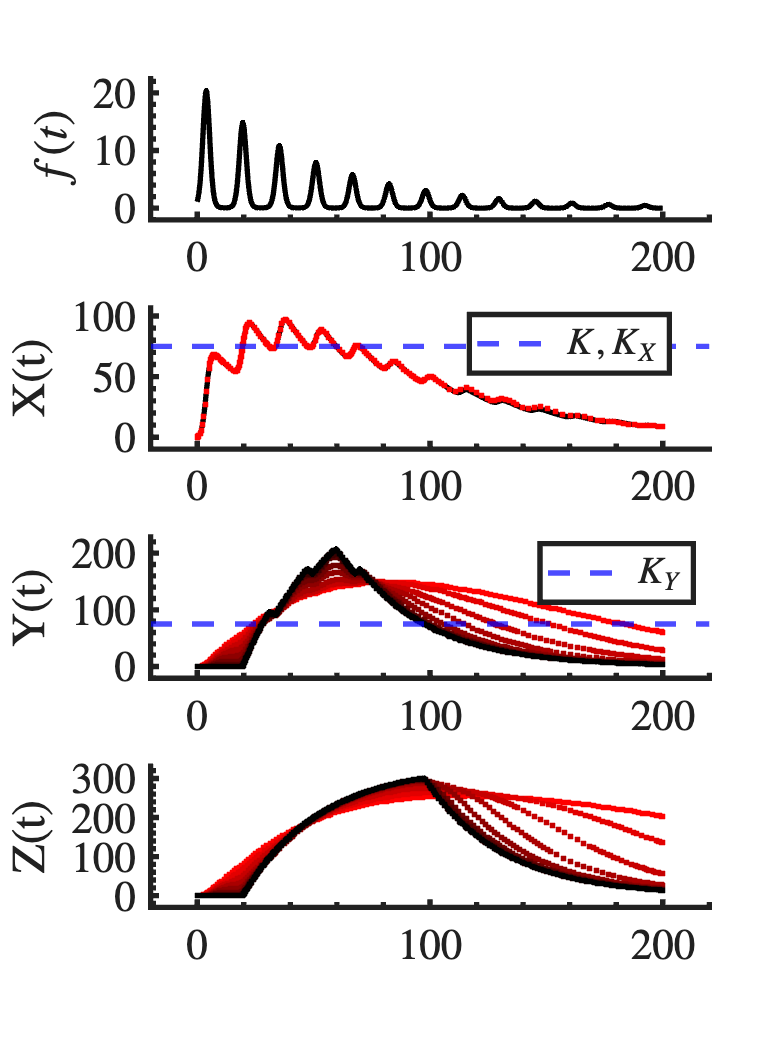

X_t = out(1,:); Y_t = out(2,:); Z_t = out(3,:); 

subplot(4,1,1); hold on;
plot(t,f_input(t),'k')
ylabel('$f(t)$')
subplot(4,1,2); hold on;
plot(t,X_t,'k','HandleVisibility','off')
scatter(t_out,L_out(:,1),'.r','HandleVisibility','off')
yline(K,'--b','DisplayName','$K,K_X$');
legend('Location','best');
ylabel('X(t)')
subplot(4,1,3); hold on;
plot(t,Y_t,'k','HandleVisibility','off')
yline(K_Y,'--b','DisplayName','$K_Y$');
legend('Location','best');
ylabel('Y(t)')
subplot(4,1,4);hold on;
plot(t,Z_t,'k','HandleVisibility','off')
ylabel('Z(t)')
PrettyFig;
if yes_save
    fig = gcf;
    fig.Units = 'inches';
    fig.Position = [0, 0, 9, 12]; 
    
    allAxes = findall(fig, 'type', 'axes');
    set(allAxes, 'FontSize', 16);
    exportgraphics(gcf, fullfile('/Users/ethan/Desktop/Alles/phd/classes/ENAS 1940/project', 'plot.pdf'), 'ContentType', 'vector');
end

## Problem 3.1a

Mutually inhibitory network,


$$\pmatrix{\dot{A}\cr \dot{B}}=\pmatrix{3& -1 \cr -1& 1}\pmatrix{A\cr B}$$


with the initial value $\pmatrix{1 \cr 1}$.

This has the solution


$$\pmatrix{A(t)\cr B(t)}=\pmatrix{(-1-\sqrt{2})e^{(2+\sqrt{2})t}& (-1+\sqrt{2})e^{(2-\sqrt{2})t}\cr e^{(2+\sqrt{2})t} & e^{(2-\sqrt{2})t}}\pmatrix{\frac{1-\sqrt{2}}{2}\cr\frac{\sqrt{2}+1}{2}}$$


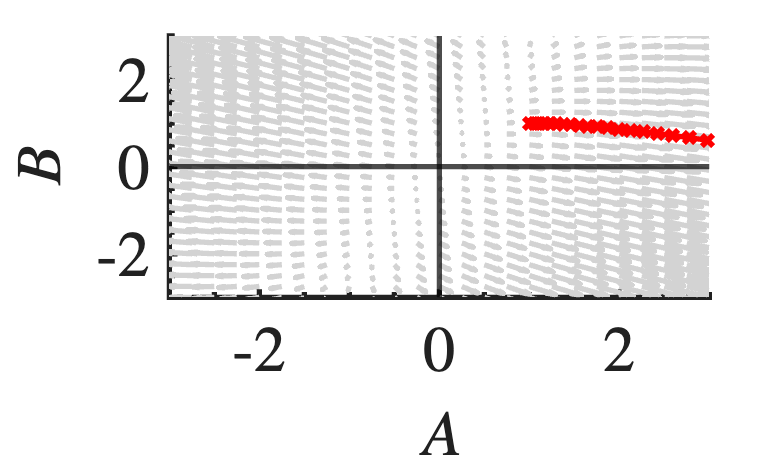

% ODE
function out = mutual_inh(t, L)
    A = L(1);
    B = L(2);
    dAdt = 3*A-B;
    dBdt = -A+B;
    out  = [dAdt; dBdt];
end

% exact solution
function out = mutual_inh_exact(t,c)
    matrices = zeros(2,2,length(t));
    matrices(1,1,:) = (-1-sqrt(2)).*exp((2+sqrt(2)).*t);
    matrices(1,2,:) = (-1+sqrt(2)).*exp((2-sqrt(2)).*t);
    matrices(2,1,:) = exp((2+sqrt(2)).*t);
    matrices(2,2,:) = exp((2-sqrt(2)).*t);
    
    out = arrayfun(@(i) matrices(:,:,i) * c, 1:length(t), 'UniformOutput', false);
    out = cell2mat(out)';
end

% initial conditions and time 
A0 = 1; B0 = 1;
tmin = 0;
tmax = 1;
tstep = 0.01;

% numerical algorithm
F = @(t,L) mutual_inh(t, L);
[t_out, L_out] = ode45(F, [tmin tmax], [A0; B0]);

% exact solution
t = tmin:tstep:tmax;
c = [(1-sqrt(2))/2; (sqrt(2)+1)/2];
out = mutual_inh_exact(t,c);

% quiver 
figure; hold on;
[A,B]=meshgrid(-3:.25:3,-3:.25:3);
dAdt = 3.*A-B;
dBdt = -A+B;
quiver(A,B,dAdt,dBdt,2,'color','#D3D3D3');

% plot solutions
plot(out(:,1),out(:,2),'r')
scatter(L_out(:,1),L_out(:,2),'rx')
yline(0,'k-');
xline(0,'k-');

ylim([-3,3])
xlim([-3,3])
xlabel("$A$")
ylabel("$B$")
PrettyFig;

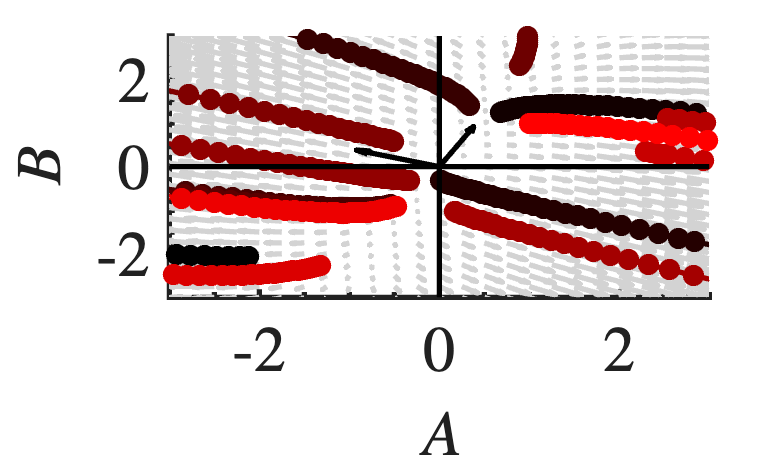


% for-loop version for multiple initial conditions and add the (1,1)
n_inits = 15;
inits = zeros(2,n_inits);
inits(1,:) = randn(1,n_inits); 
inits(2,:) = randn(1,n_inits); 
inits(1,end)=1;
inits(2,end)=1;

% plotting
cmap = [linspace(0, 1, n_inits)', zeros(n_inits, 1), zeros(n_inits, 1)]; % lines(n_inits);
figure; hold on;
[A,B]=meshgrid(-3:.25:3,-3:.25:3);
dAdt = 3.*A-B;
dBdt = -A+B;
quiver(A,B,dAdt,dBdt,2,'color','#D3D3D3');
ylim([-3,3])
xlim([-3,3])
xlabel("$A$")
ylabel("$B$")

% loop through initial conditions
for i=1:n_inits
    % initial conditon
    A0 = inits(1,i); B0 = inits(2,i); 

    % numerical algorithm
    F = @(t,L) mutual_inh(t, L);
    [t_out, L_out] = ode45(F, [tmin tmax], [A0; B0]);

    % compute c for exact solution
    a11 = (-1-sqrt(2)).*exp((2+sqrt(2)).*0);
    a12 = (-1+sqrt(2)).*exp((2-sqrt(2)).*0);
    a21 = exp((2+sqrt(2)).*0);
    a22 = exp((2-sqrt(2)).*0);
    
    Psi0 = [[a11,a12];[a21,a22]];
    Psi0_inv = inv(Psi0);
    c = Psi0_inv*inits(:,i);
    out = mutual_inh_exact(t,c);

    % plot solutions
    plot(out(:,1),out(:,2),'Color',cmap(i,:))
    scatter(L_out(:,1),L_out(:,2),'filled','MarkerFaceColor',cmap(i,:),'MarkerEdgeColor', cmap(i,:),'Marker','o')
    yline(0,'k-');
    xline(0,'k-');
end

% plot eigenvectors 
v1 = [-1-sqrt(2); 1];
v1 = v1/norm(v1);
v2 = [-1+sqrt(2); 1];
v2 = v2/norm(v2);
quiver(0, 0, v1(1), v1(2), 0, 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
quiver(0, 0, v2(1), v2(2), 0, 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
PrettyFig;

## Problem 3.1b

Mutually inhibitory network,


$$\pmatrix{\dot{A}\cr \dot{B}}=\pmatrix{3& -2 \cr 2& -1}\pmatrix{A\cr B}$$


with the initial value $\pmatrix{2 \cr 1}$.

This has the solution


$$\pmatrix{A(t)\cr B(t)}=\pmatrix{e^t& te^t+0.5e^t\cr e^t & te^t}\pmatrix{1\cr 2}$$


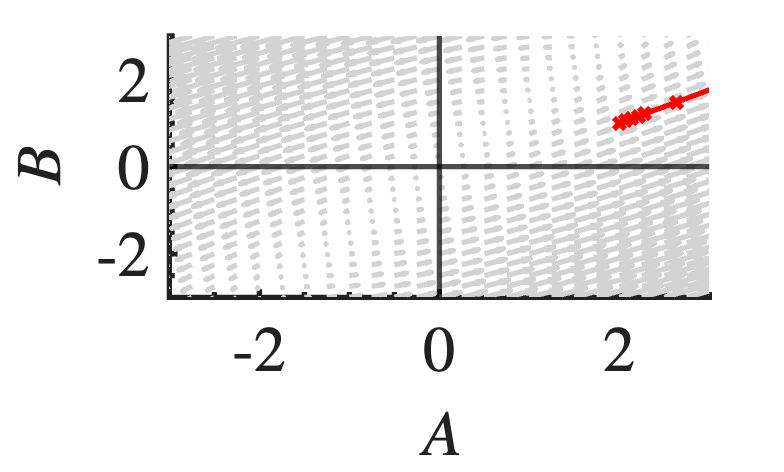

% ODE
function out = act_inh(t, L)
    A = L(1);
    B = L(2);
    dAdt = 3*A-2*B;
    dBdt = 2*A-B;
    out  = [dAdt; dBdt];
end

% exact solution
function out = act_inh_exact(t,c)
    matrices = zeros(2,2,length(t));
    matrices(1,1,:) = exp(t);
    matrices(1,2,:) = t.*exp(t)+0.5*exp(t);
    matrices(2,1,:) = exp(t);
    matrices(2,2,:) = t.*exp(t);
    
    out = arrayfun(@(i) matrices(:,:,i) * c, 1:length(t), 'UniformOutput', false);
    out = cell2mat(out)';
end

% initial conditions and time 
A0 = 2; B0 = 1;
tmin = 0;
tmax = 3;
tstep = 0.01;

% numerical algorithm
F = @(t,L) act_inh(t, L);
[t_out, L_out] = ode45(F, [tmin tmax], [A0; B0]);

% exact solution
t = tmin:tstep:tmax;
c = [1;2];
out = act_inh_exact(t,c);

% quiver 
figure(); hold on;
[A,B]=meshgrid(-3:.25:3,-3:.25:3);
dAdt = 3.*A-2.*B;
dBdt = 2.*A-B;
quiver(A,B,dAdt,dBdt,2,'color','#D3D3D3');

% plot solutions
plot(out(:,1),out(:,2),'r')
scatter(L_out(:,1),L_out(:,2),'rx')
yline(0,'k-');
xline(0,'k-');

ylim([-3,3])
xlim([-3,3])
xlabel("$A$")
ylabel("$B$")
PrettyFig;

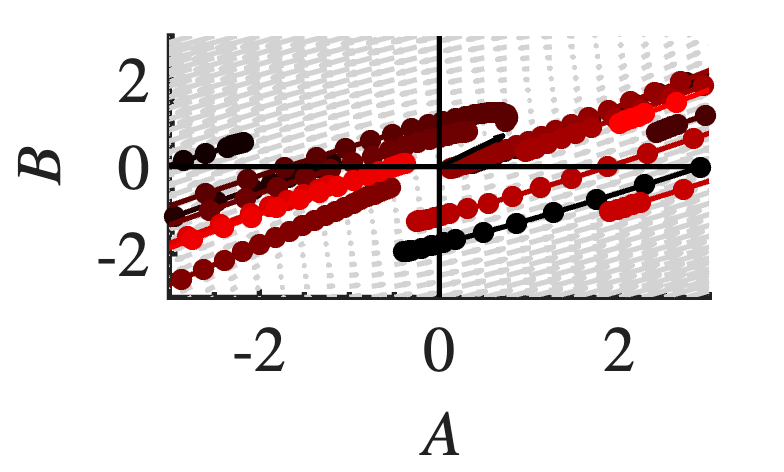


% for-loop version for multiple initial conditions and add the (1,1)
n_inits = 15;
inits = zeros(2,n_inits);
inits(1,:) = randn(1,n_inits); 
inits(2,:) = randn(1,n_inits); 
inits(1,end)=2;
inits(2,end)=1;



% plotting
cmap = [linspace(0, 1, n_inits)', zeros(n_inits, 1), zeros(n_inits, 1)]; % lines(n_inits); % lines(n_inits);
figure; hold on;
[A,B]=meshgrid(-3:.25:3,-3:.25:3);
dAdt = 3.*A-2.*B;
dBdt = 2.*A-B;
quiver(A,B,dAdt,dBdt,2,'color','#D3D3D3');
ylim([-3,3])
xlim([-3,3])
xlabel("$A$")
ylabel("$B$")

% loop through initial conditions
for i=1:n_inits
    % initial conditon
    A0 = inits(1,i); B0 = inits(2,i); 

    % numerical algorithm
    F = @(t,L) act_inh(t, L);
    [t_out, L_out] = ode45(F, [tmin tmax], [A0; B0]);

    % compute c for exact solution
    a11 = exp(0);
    a12 = 0.*exp(0)+0.5*exp(0);
    a21 = exp(0);
    a22 = 0.*exp(0);
        
    Psi0 = [[a11,a12];[a21,a22]];
    Psi0_inv = inv(Psi0);
    c = Psi0_inv*inits(:,i);
    out = act_inh_exact(t,c);

    % plot solutions
    plot(out(:,1),out(:,2),'Color',cmap(i,:))
    scatter(L_out(:,1),L_out(:,2),'filled','MarkerFaceColor',cmap(i,:),'MarkerEdgeColor', cmap(i,:),'Marker','o')
    yline(0,'k-');
    xline(0,'k-');
end

% plot eigenvectors 
v1 = [1; 1];
v1 = v1/norm(v1);
% v2 = [0.5; 0];
% v2 = v2/norm(v2);
quiver(0, 0, v1(1), v1(2), 0, 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
% quiver(0, 0, v2(1), v2(2), 0, 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
PrettyFig;

## Problem 3.2

Mutual inhibition, nonlinear

#### Plot of the flowfield with nullclines

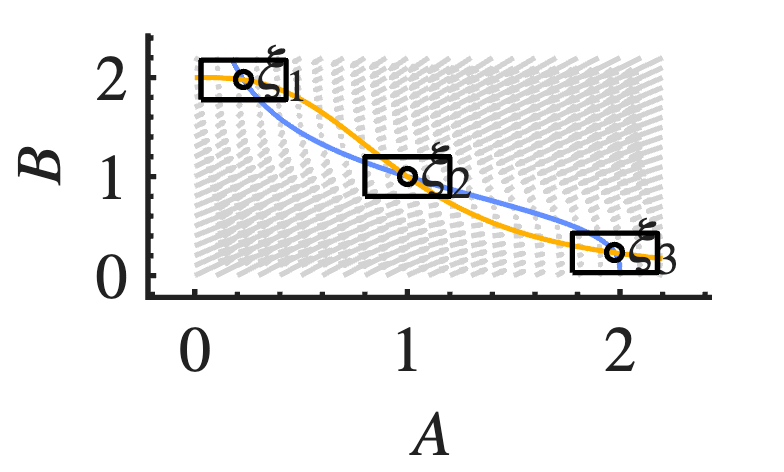

% quiver 
figure(); hold on;
[A,B]=meshgrid(0:.1:2.2,0:.1:2.2);
dAdt = 2./(1+B.^3)-A;
dBdt = 2./(1+A.^3)-B;
quiver(A,B,dAdt,dBdt,2,'color','#D3D3D3');


% nullclines
x = linspace(0,2.2,1000);
y = linspace(0,2.2,1000);
x_a = 2./(1+y.^3);
y_b = 2./(1+x.^3);
h1 = plot(x_a,y,'Color','#648FFF');
h2 = plot(x,y_b,'Color','#FFB000');

% fixed points
xi2_1 = 0.22943685978;
xi2_2 = 1.97613257061;
scatter(1,1,'ko')
scatter(xi2_1,xi2_2,'ko')
scatter(xi2_2,xi2_1,'ko')
text(1+0.03,1+0.08, '$\xi_2$','FontSize',10);
text(xi2_1+0.03,xi2_2+0.08, '$\xi_1$','FontSize',10);
text(xi2_2+0.03,xi2_1+0.08, '$\xi_3$','FontSize',10);
% legend([h1,h2], '\dot{A}=0', '\dot{B}=0');

% boxes
xbox = [0.8 1.2 1.2 0.8 0.8];
ybox = [0.8 0.8 1.2 1.2 0.8];
plot(xbox, ybox, 'k-', 'LineWidth', 1.5);
xbox = [xi2_1-0.2 xi2_1+0.2 xi2_1+0.2 xi2_1-0.2 xi2_1-0.2];
ybox = [xi2_2-0.2 xi2_2-0.2 xi2_2+0.2 xi2_2+0.2 xi2_2-0.2];
plot(xbox, ybox, 'k-', 'LineWidth', 1.5);
xbox = [xi2_2-0.2 xi2_2-0.2 xi2_2+0.2 xi2_2+0.2 xi2_2-0.2];
ybox = [xi2_1-0.2 xi2_1+0.2 xi2_1+0.2 xi2_1-0.2 xi2_1-0.2];
plot(xbox, ybox, 'k-', 'LineWidth', 1.5);

% labels
xlabel('$A$')
ylabel('$B$')
PrettyFig;

#### Examining behavior of linear approximation around $\xi_2$

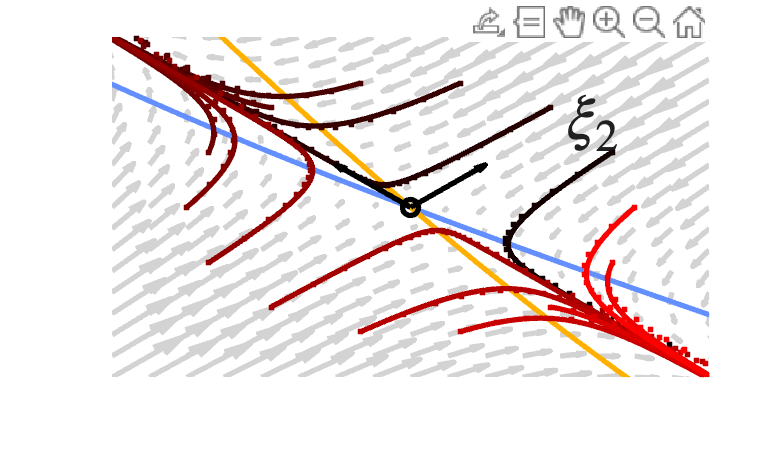

% ODE
function out = mut_inh_nonlinear(t, L)
    A = L(1);
    B = L(2);
    dAdt = 2./(1+B.^3)-A;
    dBdt = 2./(1+A.^3)-B;
    out  = [dAdt; dBdt];
end 

% exact solution xi2
function out = xi2_linear(t,init)
    xi = [1;1];
    init_origin = init-xi;

    % compute c for exact solution
    a11 = exp((-5/2).*0);
    a12 = -exp((1/2).*0);
    a21 = exp((-5/2).*0);
    a22 =  exp((1/2).*0);
        
    Psi0 = [[a11,a12];[a21,a22]];
    Psi0_inv = inv(Psi0);
    c = Psi0_inv*init_origin;
    
    matrices = zeros(2,2,length(t));
    matrices(1,1,:) = exp((-5/2).*t);
    matrices(1,2,:) = -exp((1/2).*t);
    matrices(2,1,:) = exp((-5/2).*t);
    matrices(2,2,:) =  exp((1/2).*t);
    
    out = arrayfun(@(i) matrices(:,:,i) * c, 1:length(t), 'UniformOutput', false);
    out = cell2mat(out)' + xi';
end

% exact solution xi1
function out = xi1_linear(t,init)
    xi = [0.22943685978;1.97613257061];
    init_origin = init-xi;

    % compute c for exact solution
    a11 = exp(-1.30835.*0);
    a12 = -exp(-0.691646.*0);
    a21 = exp(-1.30835.*0);
    a22 = exp(-0.691646.*0);
        
    Psi0 = [[a11,a12];[a21,a22]];
    Psi0_inv = inv(Psi0);
    c = Psi0_inv*init_origin;
    
    matrices = zeros(2,2,length(t));
    matrices(1,1,:) = exp(-1.30835.*t);
    matrices(1,2,:) = -exp(-0.691646.*t);
    matrices(2,1,:) = exp(-1.30835.*t);
    matrices(2,2,:) = exp(-0.691646.*t);
    
    out = arrayfun(@(i) matrices(:,:,i) * c, 1:length(t), 'UniformOutput', false);
    out = cell2mat(out)' + xi';
end

% exact solution xi3
function out = xi3_linear(t,init)
    xi = [1.97613257061;0.22943685978];
    init_origin = init-xi;

    % compute c for exact solution
    a11 = exp(-1.30835.*0);
    a12 = -exp(-0.691646.*0);
    a21 = exp(-1.30835.*0);
    a22 = exp(-0.691646.*0);
        
    Psi0 = [[a11,a12];[a21,a22]];
    Psi0_inv = inv(Psi0);
    c = Psi0_inv*init_origin;
    
    matrices = zeros(2,2,length(t));
    matrices(1,1,:) = exp(-1.30835.*t);
    matrices(1,2,:) = -exp(-0.691646.*t);
    matrices(2,1,:) = exp(-1.30835.*t);
    matrices(2,2,:) = exp(-0.691646.*t);
    
    out = arrayfun(@(i) matrices(:,:,i) * c, 1:length(t), 'UniformOutput', false);
    out = cell2mat(out)' + xi';
end

% quiver 
xi2_1 = 0.22943685978;
xi2_2 = 1.97613257061;
origin =  [1;1];
figure(); hold on;
[A,B]= meshgrid((origin(1)-0.2):.025:(origin(1)+0.2),(origin(2)-0.2):.025:(origin(2)+0.2));
dAdt = 2./(1+B.^3)-A;
dBdt = 2./(1+A.^3)-B;
quiver(A,B,dAdt,dBdt,2,'color','#D3D3D3');


% nullclines
x = linspace((origin(1)-0.2),(origin(1)+0.2),1000);
y = linspace((origin(2)-0.2),(origin(2)+0.2),1000);
x_a = 2./(1+y.^3);
y_b = 2./(1+x.^3);
h1 = plot(x_a,y,'Color','#648FFF','LineWidth',20);
h2 = plot(x,y_b,'Color','#FFB000','LineWidth',20);

% fixed points
scatter(1,1,'ko')
scatter(xi2_1,xi2_2,'ko')
scatter(xi2_2,xi2_1,'ko')
% text(1+0.01,1+0.003, '$\xi_2$','FontSize',10);
% text(xi2_1+0.019,xi2_2+0.015, '$\xi_1$','FontSize',10);
% text(xi2_2+0.019,xi2_1+0.015, '$\xi_3$','FontSize',10);
text(1+0.1,1+0.1, '$\xi_2$','FontSize',10);
text(xi2_1+0.1,xi2_2+0.1, '$\xi_1$','FontSize',10);
text(xi2_2+0.1,xi2_1+0.1, '$\xi_3$','FontSize',10);
% legend([h1,h2], '\dot{A}=0', '\dot{B}=0');

% time
tmin = 0;
tmax = 15;
tstep = 0.01;
t = tmin:tstep:tmax;

% initial conditions (unit circle)
n_inits = 15;
epsilon = 0.15; % distance from the fixed point
inits = zeros(2,n_inits);
inits(1,:) = real(exp(linspace(0,2,n_inits)*pi*1i)).*epsilon+origin(1);
inits(2,:) = imag(exp(linspace(0,2,n_inits)*pi*1i)).*epsilon+origin(2);

% loop through initial conditions
cmap = [linspace(0, 1, n_inits)', zeros(n_inits, 1), zeros(n_inits, 1)]; 
for i=1:n_inits
    % initial conditon
    A0 = inits(1,i); B0 = inits(2,i); 

    % numerical algorithm
    F = @(t,L) mut_inh_nonlinear(t, L);
    [t_out, L_out] = ode45(F, [tmin tmax], [A0; B0]);

    % linearized solution
    out = xi2_linear(t,[A0; B0]);

    % plot solutions
    plot(out(:,1),out(:,2),'Color',cmap(i,:))
    scatter(L_out(:,1),L_out(:,2),'filled','MarkerFaceColor',cmap(i,:),'MarkerEdgeColor', cmap(i,:),'Marker','.')
    yline(0,'k-');
    xline(0,'k-');
end


% labels and limits
% xlabel('$A$')
% ylabel('$B$')
xlim([(origin(1)-0.2),(origin(1)+0.2)])
ylim([(origin(2)-0.2),(origin(2)+0.2)])
axis off

% arrows 
% plot eigenvectors 
v1 = [1; 1].*0.05;
v2 = [-1; 1].*0.05;
quiver(origin(1), origin(2), v1(1), v1(2), 0, 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
quiver(origin(1), origin(2), v2(1), v2(2), 0, 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
PrettyFig;

Combined plot of the above

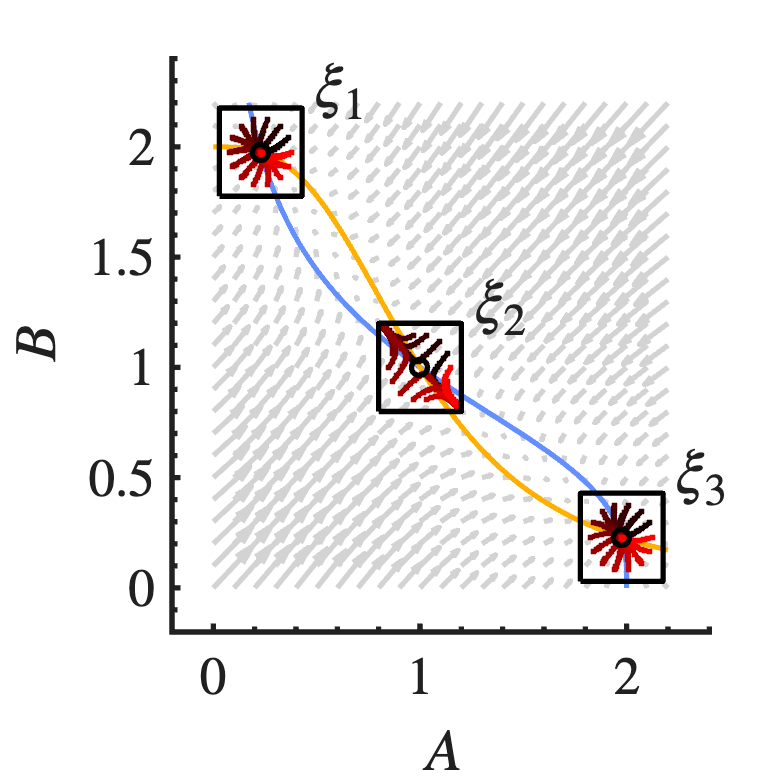

% save?
save = true;

% quiver 
figure(); hold on;
[A,B]=meshgrid(0:.1:2.2,0:.1:2.2);
dAdt = 2./(1+B.^3)-A;
dBdt = 2./(1+A.^3)-B;
quiver(A,B,dAdt,dBdt,2,'color','#D3D3D3');


% nullclines
x = linspace(0,2.2,1000);
y = linspace(0,2.2,1000);
x_a = 2./(1+y.^3);
y_b = 2./(1+x.^3);
h1 = plot(x_a,y,'Color','#648FFF');
h2 = plot(x,y_b,'Color','#FFB000');

% fixed points
xi2_1 = 0.22943685978;
xi2_2 = 1.97613257061;
text(1+0.23,1+0.28, '$\xi_2$','FontSize',10);
text(xi2_1+0.23,xi2_2+0.28, '$\xi_1$','FontSize',10);
text(xi2_2+0.23,xi2_1+0.28, '$\xi_3$','FontSize',10);
% legend([h1,h2], '\dot{A}=0', '\dot{B}=0');

% labels
xlabel('$A$')
ylabel('$B$')

% origins and plotting 
origins =  [[xi2_1;xi2_2],[1;1],[xi2_2;xi2_1]];
linear_funcs = {@xi1_linear, @xi2_linear, @xi3_linear};
for j=1:length(origins)
    origin = origins(:,j);
    % initial conditions (unit circle)
    n_inits = 15;
    epsilon = 0.15; % distance from the fixed point
    inits = zeros(2,n_inits);
    inits(1,:) = real(exp(linspace(0,2,n_inits)*pi*1i)).*epsilon+origin(1);
    inits(2,:) = imag(exp(linspace(0,2,n_inits)*pi*1i)).*epsilon+origin(2);
    
    % loop through initial conditions
    cmap = [linspace(0, 1, n_inits)', zeros(n_inits, 1), zeros(n_inits, 1)]; 
    for i=1:n_inits
        % initial conditon
        A0 = inits(1,i); B0 = inits(2,i); 
    
        % numerical algorithm
        F = @(t,L) mut_inh_nonlinear(t, L);
        [t_out, L_out] = ode45(F, [tmin tmax], [A0; B0]);
    
        % linearized solution
        out = linear_funcs{j}(t,[A0; B0]);
    
        in_box = L_out(:,1) > (origin(1)-0.2) & L_out(:,1) < (origin(1)+0.2) & ...
                 L_out(:,2) > (origin(2)-0.2) & L_out(:,2) < (origin(2)+0.2);
        L_out = L_out(in_box,:);

        in_box = out(:,1) > (origin(1)-0.2) & out(:,1) < (origin(1)+0.2) & ...
                 out(:,2) > (origin(2)-0.2) & out(:,2) < (origin(2)+0.2);
        out = out(in_box,:);
    
        % plot solutions
        scatter(L_out(:,1),L_out(:,2),'filled','MarkerFaceColor',cmap(i,:),'MarkerEdgeColor', cmap(i,:),'Marker','.')
        plot(out(:,1),out(:,2),'Color',cmap(i,:))
    end
end

% boxes
xbox = [0.8 1.2 1.2 0.8 0.8];
ybox = [0.8 0.8 1.2 1.2 0.8];
plot(xbox, ybox, 'k-', 'LineWidth', 1.5);
xbox = [xi2_1-0.2 xi2_1+0.2 xi2_1+0.2 xi2_1-0.2 xi2_1-0.2];
ybox = [xi2_2-0.2 xi2_2-0.2 xi2_2+0.2 xi2_2+0.2 xi2_2-0.2];
plot(xbox, ybox, 'k-', 'LineWidth', 1.5);
xbox = [xi2_2-0.2 xi2_2-0.2 xi2_2+0.2 xi2_2+0.2 xi2_2-0.2];
ybox = [xi2_1-0.2 xi2_1+0.2 xi2_1+0.2 xi2_1-0.2 xi2_1-0.2];
plot(xbox, ybox, 'k-', 'LineWidth', 1.5);
xlim([-0.2,2.4])
ylim([-0.2,2.4])
scatter(1,1,'ko')
scatter(xi2_1,xi2_2,'ko')
scatter(xi2_2,xi2_1,'ko')
PrettyFig;

if save
    fig = gcf;
    fig.Units = 'inches';
    fig.Position = [0, 0, 8, 8]; 
    
    allAxes = findall(fig, 'type', 'axes');
    set(allAxes, 'FontSize', 20);
    exportgraphics(gcf, fullfile('/Users/ethan/Desktop/Alles/phd/classes/ENAS 1940/project', '3.2_with_everything.pdf'), 'ContentType', 'vector');
end

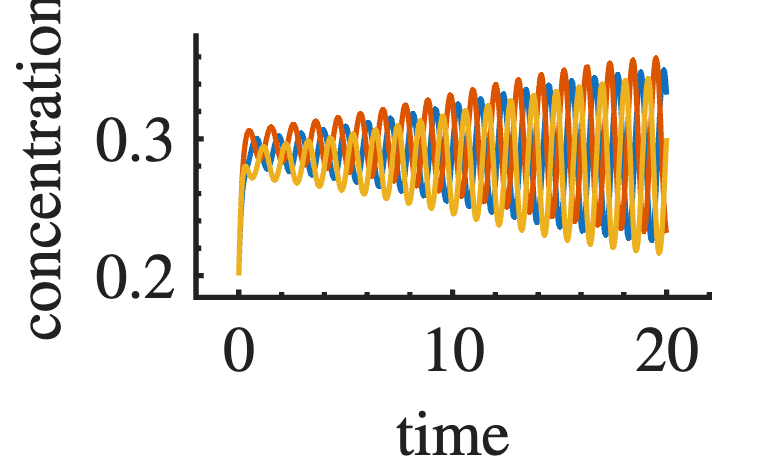

function out = repressilator(t,L,k1,k2,k3,k4,k5,k6,n1,n2,n3,K1,K2,K3)
    A = L(1);
    B = L(2);
    C = L(3);

    dAdt = k1*(1 - A) - (k2 * C.^n1) ./ (K1.^n1 + C.^n1) .* A;
    dBdt = k3*(1 - B) - (k4 * A.^n2) ./ (K2.^n2 + A.^n2) .* B;
    dCdt = k5*(1 - C) - (k6 * B.^n3) ./ (K3.^n3 + B.^n3) .* C;

    out  = [dAdt; dBdt; dCdt];
end

% parameters
k1= 0.9;   % 2.83;
k2= 100; % 489; 100 works too
k3= 1;   % 4.88;
k4= 100; % 617; 100 works too
k5= 1;
k6= 100; % 98.1; 100 work too
n1= 3;   % 3.26;
n2= 3;   % 3.34;
n3= 3;   % 3.44 ;
K1= 1;   % 0.80 ; % make this closer and closer to 1 and oscillations lost
K2= 1;   % 0.89;
K3= 1;   % 1.08;
A0=0.2;
B0=0.2;
C0=0.2;

% inits and time
tmin = 0;
tmax = 20;
tstep = 0.01;
t = tmin:tstep:tmax;

% numerical algorithm
F = @(t,L) repressilator(t, L, k1,k2,k3,k4,k5,k6,n1,n2,n3,K1,K2,K3);
[t_out, L_out] = ode45(F, [tmin tmax], [A0; B0; C0]);
figure; hold on;
plot(t_out,L_out(:,1),'DisplayName','$A$')
plot(t_out,L_out(:,2),'DisplayName','$B$')
plot(t_out,L_out(:,3),'DisplayName','$C$')
% legend('Location','best')
xlabel('time')
ylabel('concentration')
PrettyFig;

Jacobian calculation for the repressilator

xi = [0.289691; 0.296435; 0.282585];
A = xi(1); B = xi(2); C = xi(3); 

disp(sprintf('%.6g', -0.9-100*(C^3)/(1+C^3))) %#ok<*DSPSP>

-3.10677


disp(0)

     0



disp(sprintf('%.6g',A*-100*(3*C^2)/(C^3+1)^2))

-6.637



disp(sprintf('%.6g',B*-100*(3*A^2)/(A^3+1)^2))

-7.11307


disp(sprintf('%.6g',-1-100*(A^3)/(1+A^3)))

-3.37341


disp(0)

     0




disp(0)

     0



disp(sprintf('%.6g',C*-100*(3*B^2)/(B^3+1)^2))

-7.07609


disp(sprintf('%.6g',-1-100*(B^3)/(1+B^3)))

-3.53875



% syms A B C
% f = repressilator(t, [A;B;C], k1,k2,k3,k4,k5,k6,n1,n2,n3,K1,K2,K3);
% J_sym = jacobian(f, [A,B,C]);
% J = double(subs(J_sym, [A,B,C], xi'))

Plotting the repressilator

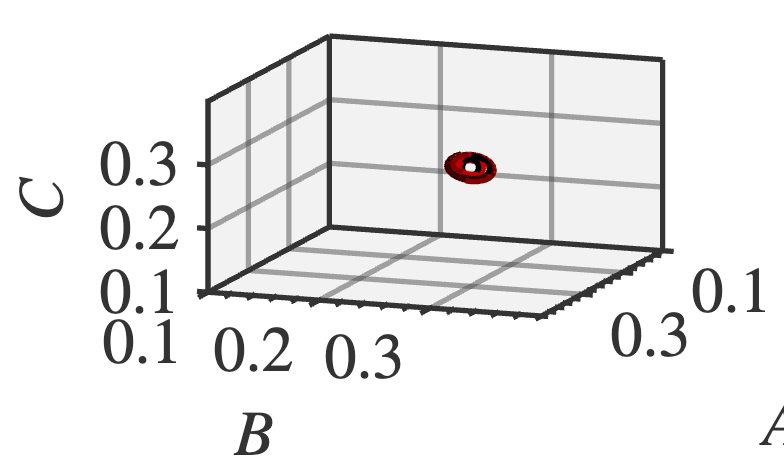

% initial conditions using parametric curve; and time
n_inits = 5;
epsilon = 0.02;
c = 20;
x = epsilon*sin(linspace(0,pi,n_inits)).*sin(linspace(0,pi,n_inits)).*cos(c*linspace(0,pi,n_inits));
y = epsilon*sin(linspace(0,pi,n_inits)).*sin(linspace(0,pi,n_inits)).*sin(c*linspace(0,pi,n_inits));
z = epsilon*cos(linspace(0,pi,n_inits));
x = x+xi(1); y = y+xi(2); z = z+xi(3);
inits = zeros(3,n_inits);
inits(1,:) = x; inits(2,:) = y; inits(3,:) = z;
cmap = [linspace(0, 1, n_inits)', zeros(n_inits, 1), zeros(n_inits, 1)]; 
tmin = 0;
tmax = 2;
tstep = 0.01;
t = tmin:tstep:tmax;

% start figure and plot fixed point
figure; hold on;
scatter3(xi(1),xi(2),xi(3),'ko')
% plot3(L_out(:,1),L_out(:,2),L_out(:,3),'k')
% plot3(inits(1,:),inits(2,:),inits(3,:),'r')

for i=1:length(inits)
    A0 = inits(1,i); B0 = inits(2,i); C0 = inits(3,i);
    F = @(t,L) repressilator(t, L, k1,k2,k3,k4,k5,k6,n1,n2,n3,K1,K2,K3);
    [t_out, L_out] = ode45(F, [tmin tmax], [A0; B0; C0]);

    plot3(L_out(:,1),L_out(:,2),L_out(:,3),'Color',cmap(i,:))
    % scatter3(L_out(:,1),L_out(:,2),L_out(:,3),'filled','MarkerFaceColor',cmap(i,:),'MarkerEdgeColor', cmap(i,:),'Marker','.')
end


% additional plotting parameters
grid on; 
box on; 
xlabel('$A$'); ylabel('$B$'); zlabel('$C$');
xlim([0.1,0.4]); ylim([0.1,0.4]); zlim([0.1,0.4])
view(110, 20);
ax = gca;
ax.Color = [0.95 0.95 0.95];       
ax.GridColor = [0.3 0.3 0.3];      
ax.GridAlpha = 0.5;                
ax.LineWidth = 1.2;
ax.XColor = [0.2 0.2 0.2];
ax.YColor = [0.2 0.2 0.2];
ax.ZColor = [0.2 0.2 0.2];
set(ax, 'GridLineStyle', '-');
% ax.Projection = 'perspective';  
PrettyFig;

Linear solution near fixed point of repressilator, compare with numerical integration of nonlinear system

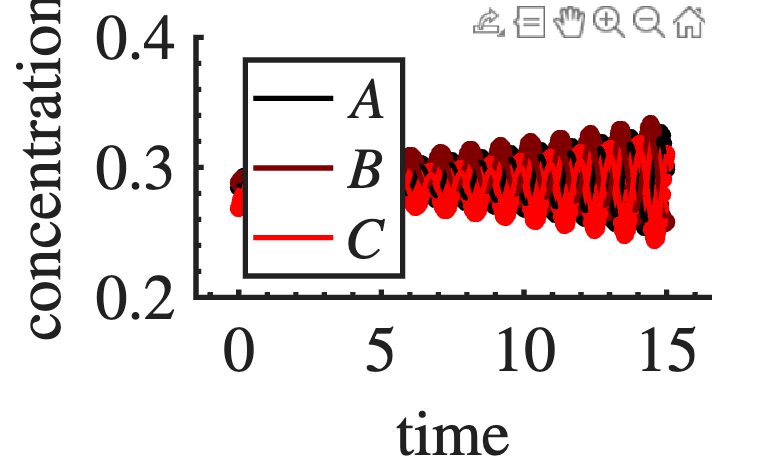

function out = repressilator_linear(t,init)
    xi = [0.289691; 0.296435; 0.282585];
    init_origin = init-xi;
    
    % eigenvalues 
    lam1 = -10.2806;
    lam2 =  0.13081 + 6.00705i;
    lam3 =  0.13081 - 6.00705i;
    
    % eigenvectors
    v1 = [0.925175; 0.952758; 1];
    v2 = [-0.461443+0.856168i; -0.518586-0.848922i; 1];
    v3 = [-0.461443-0.856168i; -0.518586+0.848922i; 1];

    % compute c for exact solution
    a11 = v1(1);
    a12 = v2(1);
    a13 = v3(1);
    a21 = v1(2);
    a22 = v2(2);
    a23 = v3(2);
    a31 = v1(3);
    a32 = v2(3);
    a33 = v3(3);
        
    Psi0 = [[a11,a12,a13];[a21,a22,a23];[a31,a32,a33]];
    Psi0_inv = inv(Psi0);
    c = Psi0_inv*init_origin;
    
    matrices = zeros(3,3,length(t));
    matrices(1,1,:) = v1(1)*exp(lam1.*t);
    matrices(1,2,:) = v2(1)*exp(lam2.*t);
    matrices(1,3,:) = v3(1)*exp(lam3.*t);
    matrices(2,1,:) = v1(2)*exp(lam1.*t);
    matrices(2,2,:) = v2(2)*exp(lam2.*t);
    matrices(2,3,:) = v3(2)*exp(lam3.*t);
    matrices(3,1,:) = v1(3)*exp(lam1.*t);
    matrices(3,2,:) = v2(3)*exp(lam2.*t);
    matrices(3,3,:) = v3(3)*exp(lam3.*t);
    
    out = arrayfun(@(i) matrices(:,:,i) * c, 1:length(t), 'UniformOutput', false);
    out = real(cell2mat(out)') + xi';
end

xi = [0.289691; 0.296435; 0.282585];

% initial condition and time
% initial_con = xi + 0.02.*randn(3,1);
initial_con = [0.2843;0.2882;0.2684];
tmin = 0;
tmax = 15;
tstep = 0.01;
t = tmin:tstep:tmax;

% numerical algorithm
F = @(t,L) repressilator(t, L, k1,k2,k3,k4,k5,k6,n1,n2,n3,K1,K2,K3);
[t_out, L_out] = ode45(F, [tmin tmax], initial_con);

% linearized solution
out = repressilator_linear(t,initial_con);

% plot
cmap = [linspace(0, 1, 3)', zeros(3, 1), zeros(3, 1)]; 
figure; hold on;
scatter(t_out,L_out(:,1),'o','MarkerFaceColor',cmap(1,:),'MarkerEdgeColor',cmap(1,:),'HandleVisibility','off')
scatter(t_out,L_out(:,2),'o','MarkerFaceColor',cmap(2,:),'MarkerEdgeColor',cmap(2,:),'HandleVisibility','off')
scatter(t_out,L_out(:,3),'o','MarkerFaceColor',cmap(3,:),'MarkerEdgeColor',cmap(3,:),'HandleVisibility','off')
plot(t, out(:,1),'Color',cmap(1,:),'DisplayName','$A$')
plot(t, out(:,2),'Color',cmap(2,:),'DisplayName','$B$')
plot(t, out(:,3),'Color',cmap(3,:),'DisplayName','$C$')
% legend('Location','best')
xlabel('time')
ylabel('concentration')
ylim([0.2,0.4])
legend('Location','best')
PrettyFig;

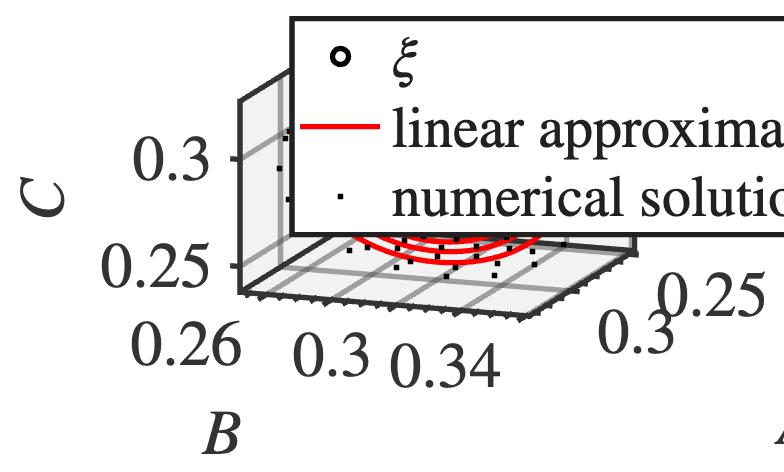


inits = [0.2843;0.2882;0.2684];
figure; hold on;
scatter3(xi(1),xi(2),xi(3),'ko','DisplayName','$\xi$')

A0 = inits(1); B0 = inits(2); C0 = inits(3);
F = @(t,L) repressilator(t, L, k1,k2,k3,k4,k5,k6,n1,n2,n3,K1,K2,K3);
[t_out, L_out] = ode45(F, [tmin tmax], [A0; B0; C0]);

plot3(out(:,1),out(:,2),out(:,3),'Color','r','DisplayName','linear approximation')
scatter3(L_out(:,1),L_out(:,2),L_out(:,3),'filled','MarkerFaceColor','k','MarkerEdgeColor', 'k','Marker','.','DisplayName','numerical solution')


% additional plotting parameters
grid on; 
box on; 
xlabel('$A$'); ylabel('$B$'); zlabel('$C$');
zoom_factor = 0.1;
% xlim([xi(1)-zoom_factor,xi(1)+zoom_factor]);
% ylim([xi(2)-zoom_factor,xi(2)+zoom_factor]);
% zlim([xi(3)-zoom_factor,xi(3)+zoom_factor]);
% legend('location','best')
xlim([0.2451 0.3343])
ylim([0.2518 0.3410])
zlim([0.2380 0.3272])
view([70.2500 13.3984])
legend(["$\xi$", "linear approximation", "numerical solution"], "Position", [0.6211 0.6510 0.2572, 0.1597])
view(110, 20);
ax = gca;
ax.Color = [0.95 0.95 0.95];       
ax.GridColor = [0.3 0.3 0.3];      
ax.GridAlpha = 0.5;                
ax.LineWidth = 1.2;
ax.XColor = [0.2 0.2 0.2];
ax.YColor = [0.2 0.2 0.2];
ax.ZColor = [0.2 0.2 0.2];
set(ax, 'GridLineStyle', '-');
set(gca, 'SortMethod', 'childorder'); 
% ax.Projection = 'perspective';  
PrettyFig;


% find major axes from solutions
[coeff_numerical,~,latent_numerical,~,explained_numerical] = pca(L_out);
[coeff_linear,~,latent_linear,~,explained_linear] = pca(out);

## Problem 4.1

Initial distribution and steady state concentration

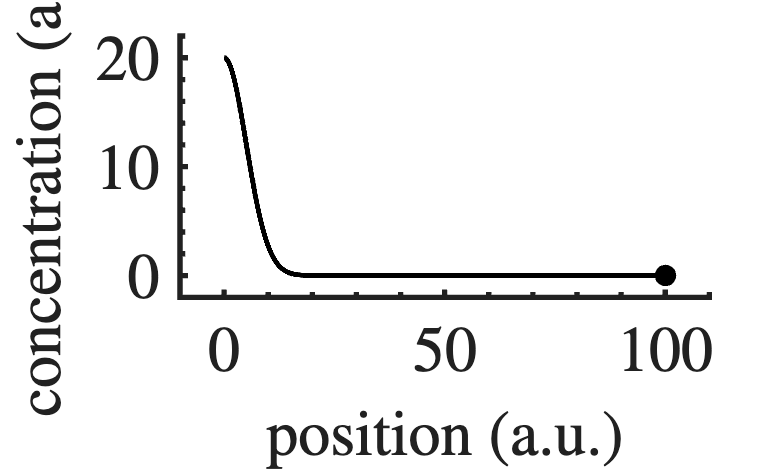

figure; hold on;
x = 0:0.01:100;
out = 20*exp((-x.^2)./(2*5^2));
plot(x,out,'k');
scatter(x(end),out(end), 'o','k')
scatter(x(end),out(end), 'o','k','filled')
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
box off;
PrettyFig

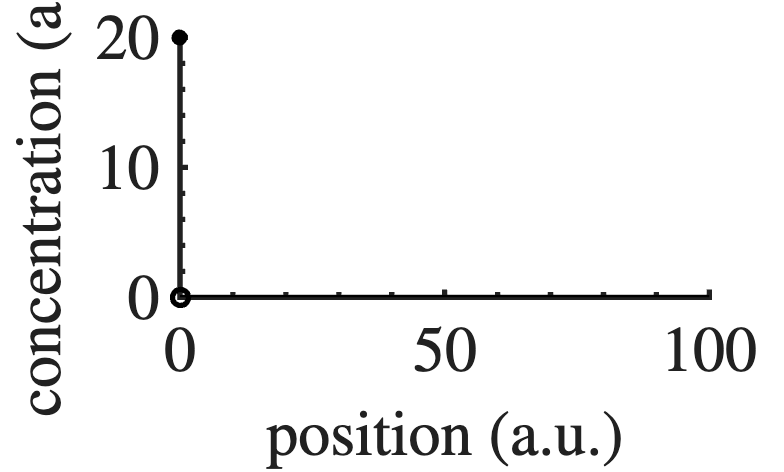


figure; hold on;
x = 0:0.01:100;
out = zeros(length(x),1);
plot(x,out,'k');
scatter(x(1),20, 'o','k','filled')
scatter(x(2),out(2), 'o','k')
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
box off;
PrettyFig

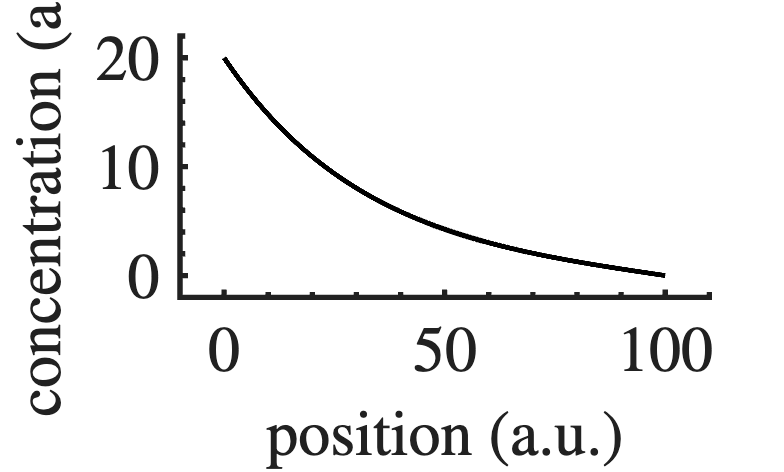


figure; hold on;
const = 0.03;
x = 0:0.01:100;
a = -20/(exp(200*const)-1);
b = 20+20/(exp(200*const)-1);
out = a*exp(const.*x)+b*exp(-const.*x);
plot(x,out,'k');
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
box off;
PrettyFig

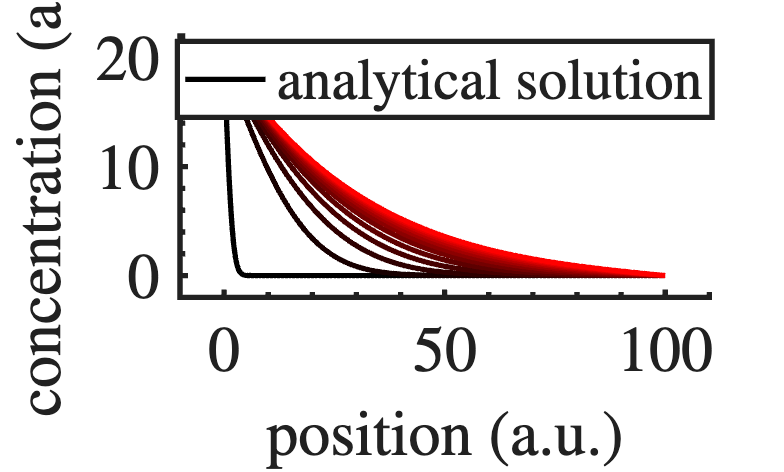


% fourier coefficients
function coeffs = morphogen_cn(k, D, N, a, b)
    n = 1:N; 
    sqrt_k_over_D = sqrt(k/D);
    exp_pos = exp(100 * sqrt_k_over_D);
    exp_neg = exp(-100 * sqrt_k_over_D);
    alternating = (-1).^n;
    term1 = -2*pi*n*a*D;
    term2 = 2*pi*n.*alternating*a*D*exp_pos;
    term3 = -2*pi*n*b*D;
    term4 = 2*pi*n.*alternating*b*D*exp_neg;
    numerator = term1 + term2 + term3 + term4;
    denominator = 10000*k + pi^2*n.^2*D;
    coeffs = numerator ./ denominator;
end

% PDE solution w(x,t)
function w = morphogen_w(t, x, D, k, c_n)
    N = length(c_n);
    n_values = 1:N;
    terms = arrayfun(@(n) c_n(n) * sin((n * pi * x) / 100) .* exp(-(k + (n^2 * pi^2 * D) / 100^2) .* t), ...
                     n_values, 'UniformOutput', false);
    w = sum(cell2mat(terms'), 1);
end
k = 0.01;  % degradation rate
D = 100/9; % diffusion coefficient
N = 1000;  % number of terms for the fourier series
a = -(20)/(exp(200*sqrt(k/D))-1);
b = 20 - a;
c_n = morphogen_cn(k, D, N, a, b);

t = 0.1:10:120;
x = 0:0.1:100;
equilibrium_sol = a*exp(sqrt(k/D).*x)+b*exp(-sqrt(k/D).*x);
cmap = [linspace(0, 1, length(t))', zeros(length(t), 1), zeros(length(t), 1)];
figure; hold on;
set(gcf, 'Renderer', 'painters');
for i=1:length(t)
    w_xt = morphogen_w(t(i), x, D, k, c_n);
    plot(x,w_xt+equilibrium_sol,'Color',cmap(i,:),'HandleVisibility','off')
end
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5);  % Dummy line
legend([h1], {'analytical solution'}, 'Location', 'best');
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
PrettyFig;

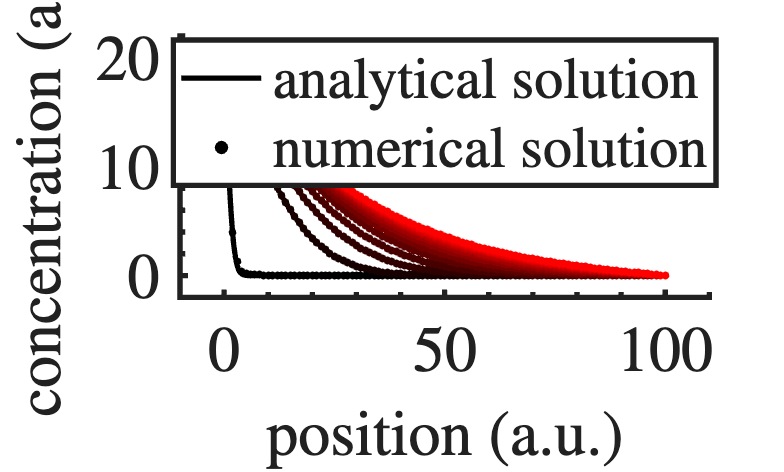

% with numerical solution
% from claude
% PDE function
function [c, f, s] = pdefun_morph(x, t, u, DuDx)
    D = 100/9;
    k = 0.01;
    c = 1;
    f = D * DuDx;
    s = -k * u;
end

% Initial condition
function u0 = icfun_morph(x)
    k = 0.01;
    D = 100/9;
    N = 1000;
    a = -(20)/(exp(200*sqrt(k/D))-1);
    b = 20 - a;
    c_n = morphogen_cn(k, D, N, a, b);
    
    u0 = zeros(size(x));
    for n = 1:N
        u0 = u0 + c_n(n) * sin(n * pi * x / 100);
    end
    u0 = u0 + a*exp(sqrt(k/D).*x) + b*exp(-sqrt(k/D).*x);
end


function [pl, ql, pr, qr] = bcfun_morph(xl, ul, xr, ur, t)
    k = 0.01;
    D = 100/9;
    a = -(20)/(exp(200*sqrt(k/D))-1);
    b = 20 - a;
    pl = ul - (a + b);
    ql = 0;
    equilibrium_100 = a*exp(100*sqrt(k/D)) + b*exp(-100*sqrt(k/D));
    pr = ur - equilibrium_100;
    qr = 0;
end

% numerical calculation
m = 0;  
x_num = linspace(0, 100, 101);
t_num = [0, 0.1:10:120];
sol = pdepe(m, @pdefun_morph, @icfun_morph, @bcfun_morph, x_num, t_num);

t = 0.1:10:120;
x = 0:0.1:100;
equilibrium_sol = a*exp(sqrt(k/D).*x)+b*exp(-sqrt(k/D).*x);

cmap = [linspace(0, 1, length(t))', zeros(length(t), 1), zeros(length(t), 1)];
figure; hold on;
set(gcf, 'Renderer', 'painters');
for i=1:length(t)
    w_xt = morphogen_w(t(i), x, D, k, c_n);
    plot(x,w_xt+equilibrium_sol,'Color',cmap(i,:),'HandleVisibility','off')
    plot(x_num, sol(i+1, :), 'o', 'Color', cmap(i,:), 'MarkerSize', 1, 'MarkerFaceColor', cmap(i,:),'HandleVisibility','off')
end
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5);  % Dummy line
h2 = plot(NaN, NaN, 'ko', 'MarkerSize', 3, 'MarkerFaceColor', 'k');  % Dummy dots

legend([h1, h2], {'analytical solution', 'numerical solution'}, 'Location', 'best');
% legend([h2], {'numerical solution'}, 'Location', 'best');
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
PrettyFig;

## Problem 4.2

Fokker-Planck equation, constant drift velocity


$$\frac{\partial p}{\partial t}=-v\frac{\partial p}{\partial x}+D\frac{\partial^2 p}{\partial x^2}$$


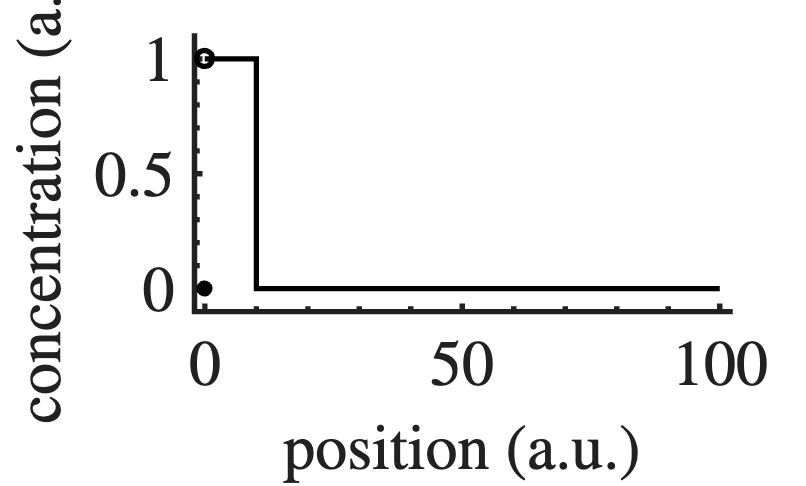

figure; hold on;
x = 0:0.01:100;
out = zeros(length(x),1);
stairs([0,10,100],[1,0,0],'k')
scatter(0,1,'ko')
scatter(0,0,'ko','filled')
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
box off;
ylim([-0.1,1.1])
xlim([-2,102])
PrettyFig;

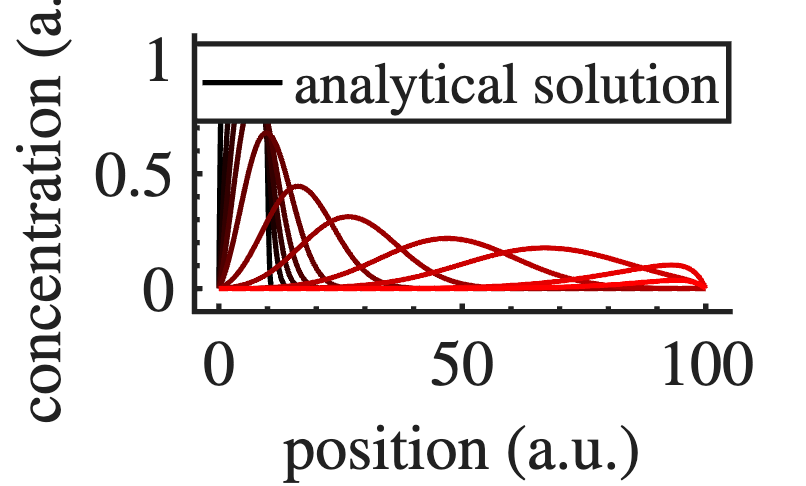


% fourier coefficients
function coeffs = fp_cn(N,D,v)
    n = 1:N; 
    term1 = 2*D*exp(-(5*v)/D);
    term2 = n.*pi*D*exp((5*v)/D);
    term3 = -50.*sin((pi.*n)./10)*v;
    term4 = -n.*pi.*D.*cos((pi.*n)/10);
    numerator = term1 .*(term2 + term3 + term4);
    denominator = 2500*v^2+n.^2.*pi^2*D^2;
    coeffs = numerator ./ denominator;
end

% pde solution p(x,t)
function out = fp_sol(t, x, D, v, c_n)
    N = length(c_n);
    n_values = 1:N;
    terms = arrayfun(@(n) c_n(n) .* exp((v/(2*D)).*x).*sin((n*pi.*x)/100).*exp(-((n^2*pi^2*D)/(100^2)+v^2/(4*D)).*t), ...
                     n_values, 'UniformOutput', false);
    out = sum(cell2mat(terms'), 1);
end

v=0.2;
D=0.5;
N=1000;

c_n = fp_cn(1000,D,v);
t = [0.1,2,5,10,20,50,100,200,300,500,610];
x = 0:0.1:100;

cmap = [linspace(0, 1, length(t))', zeros(length(t), 1), zeros(length(t), 1)];
figure; hold on;
set(gcf, 'Renderer', 'painters');
for i=1:length(t)
    out = fp_sol(t(i), x, D, v, c_n);
    plot(x,out,'Color',cmap(i,:),'HandleVisibility','off') % +(length(t)-(i-1))*0.5
end
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5);  % Dummy line
legend([h1], {'analytical solution'}, 'Location', 'best');
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
ylim([-0.1, 1.1])
xlim([-5, 105])
% ax = gca;
% ax.YTick = [];
% ax.YTickLabel = [];
% ax.YLabel.String = '';
PrettyFig;

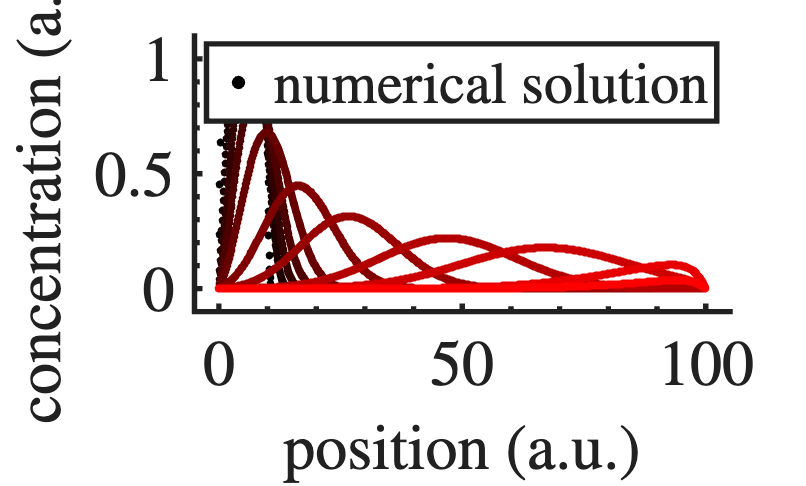

arr_sum =      2     4     6     8     1     6     6     2     3     4     5     6     3     5     4     6     3     5     4     4     2     4     2     3     4     3     3     5     8     5     8     5     5     5     4     5     3     6     6     5     3     5     7     3     5     5     6     5     4     5


arr_truth = 1×100000 logical array
   1   0   0   0   1   0   0   1   1   0   0   0   1   0   0   0   1   0   0   0   1   0   1   1   0   1   1   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   1   0   0   0   0   0   0


arr_prob = 0.2536

% with numerical solution
% from claude
% PDE function
function [c, f, s] = pdefun_fp(x, t, u, DuDx)
    D = 0.5;
    v = 0.2;
    c = 1;
    f = D * DuDx - v * u;  % advection-diffusion flux
    s = 0;
end

% Initial condition
function u0 = icfun_fp(x)
    if x <= 10
        u0 = 1;
    else
        u0 = 0;
    end
end

% Boundary conditions
function [pl, ql, pr, qr] = bcfun_fp(xl, ul, xr, ur, t)
    pl = ul;   % p(0,t) = 0
    ql = 0;
    pr = ur;   % p(100,t) = 0
    qr = 0;
end

% numerical calculation
m = 0;
x_num = linspace(0, 100, 1001);
t_num = [0, 0.1, 2, 5, 10, 20, 50, 100, 200, 300, 500, 610];
sol = pdepe(m, @pdefun_fp, @icfun_fp, @bcfun_fp, x_num, t_num);

% parameters
v = 0.2;
D = 0.5;
N = 1000;
c_n = fp_cn(N, D, v);

t = [0.1, 2, 5, 10, 20, 50, 100, 200, 300, 500, 610];
x = 0:0.1:100;

cmap = [linspace(0, 1, length(t))', zeros(length(t), 1), zeros(length(t), 1)];
figure; hold on;
set(gcf, 'Renderer', 'painters');
for i = 1:length(t)
    % analytical solution
    out = fp_sol(t(i), x, D, v, c_n);
    % plot(x, out, 'Color', cmap(i,:), 'HandleVisibility', 'off')
    % numerical solution (t_num index: i+1 because t_num starts at 0)
    plot(x_num, sol(i+1, :), 'o', 'Color', cmap(i,:), 'MarkerSize', 1, ...
         'MarkerFaceColor', cmap(i,:), 'HandleVisibility', 'off')
end

h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5);
h2 = plot(NaN, NaN, 'ko', 'MarkerSize', 3, 'MarkerFaceColor', 'k');
% legend([h1, h2], {'analytical solution', 'numerical solution'}, 'Location', 'best');
legend([h2], {'numerical solution'}, 'Location', 'best');
xlabel('position (a.u.)')
ylabel('concentration (a.u.)')
box off;
ylim([-0.1, 1.1])
xlim([-5, 105])
PrettyFig;